# Creating synthetic microbial communities of heterotrophs and phototrophs for bioproduction

**Cristal Zuñiga1, Ting-Ting Li2, Michael T. Guarnieri3, Jackson Paul2, Chien-Ting Li2, Michael J. Betenbaugh2, Karsten Zengler*1,4,5**

1 Department of Pediatrics, University of California, San Diego, 9500 Gilman Drive, La Jolla, CA 92093-0760, USA

2 Department of Chemical and Biomolecular Engineering, The Johns Hopkins University, 3400 North Charles Street, Baltimore, MD 21218, USA 

3. National Bioenergy Center, National Renewable Energy Laboratory, Golden, CO 80401, USA

4 Center for Microbiome Innovation, University of California, San Diego, 9500 Gilman Drive, La Jolla, CA 92093-0403, USA

5 Department of Bioengineering, University of California, San Diego, 9500 Gilman Drive, La Jolla, CA 92093-0760, USA

# Abstract

Microbial communities comprised of phototrophs and heterotrophs hold great promise for sustainable biotechnology. Successful application of these communities for bioproduction relies on the selection of partners and knowledge about interactions and exchanges. To this end, we constructed four community metabolic models to guide strain selection of synthetic communities for photosynthetic bioproduction. The metabolic models of a sucrose-secreting *Synechococcus elongatus,* two strains of *Escherichia coli*, *Yarrowia lipolytica*, and *Bacillus subtilis *were paired in phototroph-heterotroph combinations. We elucidated metabolic exchanges that sustain the heterotroph in minimal media devoid of any organic carbon source. Growth phenotypes and reaction flux predictions were validated using physiological and expression data, while confirming metabolic interactions and potential production capabilities by targeted and untargeted global metabolomics. We unraveled member-specific metabolic bottlenecks (e.g. histidine- and transport-related reactions) and evaluated how microbial communities redirect metabolic fluxes to bypass them. Additionally, we confirmed compensation for lethal genetic traits, achieving up to 27% recovery from lethal knockouts. 

 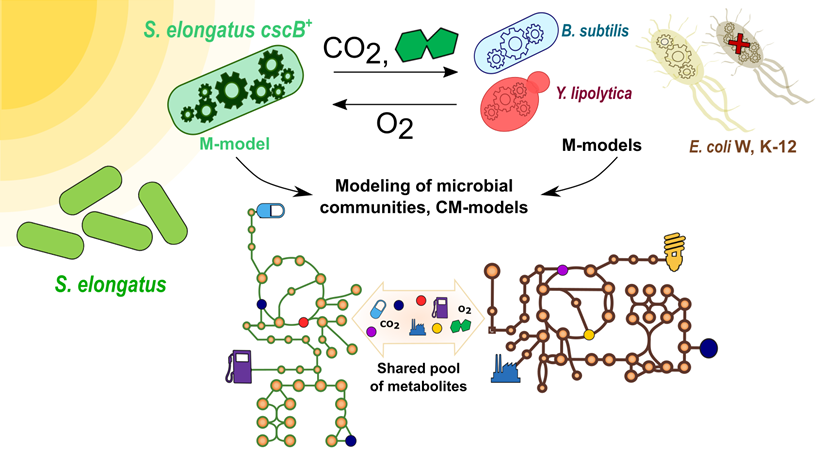

%Cristal Zuniga
%All_cyano
% 2.1.2018
%initCobraToolbox
load('SingleM.mat')
load('modelsCo.mat')
load('modelCo2.mat')
load('SingleM.mat')

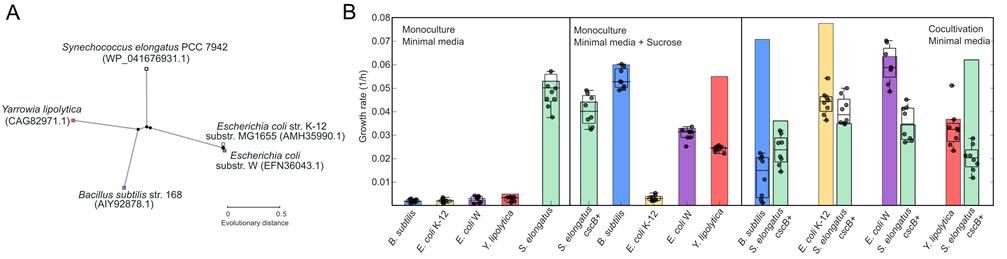

**Figure 1. Community members and growth performance.** 

(A) Neighbor-joining tree based of almost full-length 16S rRNA gene sequences, showing phylogenetic relationships between *S. elongatus* PCC 7942 and the heterotrophic species used here. Numbers at nodes indicate bootstrap values from 1,000 replicates. GenBank accession numbers are given in parentheses. 

(B) The bar plot depicts growth rates predicted using CM-models. Boxplots show experimental validation using at least six experimental replicates, the central mark indicates the median, and the bottom and top edges of the box indicate the 25th and 75th percentiles, respectively. The whiskers extend to the most extreme data points not considered outliers. The first panel shows growth in monoculture using minimal media without an organic carbon source. The second panel shows growth rates during monoculture, while using minimal media with additional sucrose. The third panel shows results obtained when combining *S. elongatus* *cscB*+ with all heterotrophs in minimal media. 

%Constraints
[a b] = exchangeCombinedModel(modelsCo{1})

a = 70×8 table
    Index          A_Rxn                 B_Name                  C_eq                Met          D_lb      E_ub       Flux    
    _____    __________________    __________________    _____________________    __________    ________    ____    ___________

    1852     'EX_acgam_[smp]'      'EX_acgam_[smp]'      'acgam_[smp]  <=> '      'acgam_'             0       0              0
    1853     'EX_adn_[smp]'        'EX_adn_[smp]'        'adn_[smp]  <=> '        'adn_'               0       0              0
    1854     'EX_arg__L_[smp]'     'EX_arg__L_[smp]'     'arg__L_[smp]  <=> '     'arg__L_'            0    1000              0
    1855     'EX_asn__L_[smp]'     'EX_asn__L_[smp]'     'asn__L_[smp]  

b = 35×8 table
    Index          A_Rxn                 B_Name                  C_eq                Met          D_lb      E_ub       Flux    
    _____    __________________    __________________    _____________________    __________    ________    ____    ___________

    1856     'EX_ca2_[smp]'        'EX_ca2_[smp]'        'ca2_[smp]  <=> '        'ca2_'          -0.024    1000    -0.00022688
    1857     'EX_co2_[smp]'        'EX_co2_[smp]'        'co2_[smp]  <=> '        'co2_'           -1.99    1000          -1.99
    1858     'EX_cobalt2_[smp]'    'EX_cobalt2_[smp]'    'cobalt2_[smp]  <=> '    'cobalt2_'    -1.7e-05    1000    -1.8448e-07
    1859     'EX_cu2_[smp]'        'EX_cu2_[smp]'        'cu2_[smp]  <=>

[a b] = exchangeCombinedModel(modelsCo{2});
[a b] = exchangeCombinedModel(modelsCo{3});
[a b] = exchangeCombinedModel(modelsCo{4});

[a b] = exchangeSingleModel(SingleM{1});
[a b] = exchangeSingleModel(SingleM{2});
[a b] = exchangeSingleModel(SingleM{3});
[a b] = exchangeSingleModel(SingleM{4});
[a b] = exchangeSingleModel(SingleM{5});
[a b] = exchangeSingleModel(SingleM{6});


for i=1:numel(SingleM)
   FBA=optimizeCbModel(SingleM{i,1});
    GrI(i,1)= FBA.f;
    SP{i,1}=FBA.y;
end

for i=1:numel(modelsCo)
   FBA=optimizeCbModel(modelsCo{i,1});
   BOF=find(modelsCo{i,1}.c);
   SP_Co{i,1}=FBA.y;
   GrCo(i,1)= FBA.x(BOF(1));
   GrCo(i,2)= FBA.x(BOF(2));
end

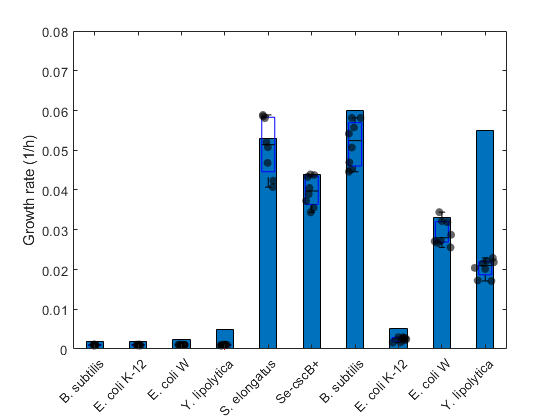

%Figure 1 separated bars

figure
PredictionsM=[0.002;0.002;0.0025;0.005;0.0530000000000000;0.0440000000000000;0.0600000000000000;0.005200000000000000;0.0330000000000000;0.0550000000000000];
Experimental=[0.00100000000000000;0.00100000000000000;0.00100000000000000;0.00100000000000000;0.0500000000000000;0.0400000000000000;0.0520000000000000;0.00240000000000000;0.0300000000000000;0.0200000000000000];
Error=[1.50000000000000e-04;1.50000000000000e-04;1.50000000000000e-04;1.50000000000000e-04;0.0100000000000000;0.00700000000000000;0.00780000000000000;0.00110000000000000;0.00450000000000000;0.00300000000000000];
bar(PredictionsM,0.4)
somenames={'B. subtilis';'E. coli K-12';'E. coli W';'Y. lipolytica';'S. elongatus'; 'Se-cscB+'; 'B. subtilis';'E. coli K-12';'E. coli W';'Y. lipolytica' };

hold on
ylabel('Growth rate (1/h)')
box on

Dots=[0.00103658618246335,0.00110435212152736,0.00112288075955837,0.00106126997185019,0.0588842061773607,0.0433212032171510,0.0541675208718030,0.00160263866242847,0.0255616148051487,0.0229210924999134;0.000872537130205993,0.00100138487406290,0.00108338273835495,0.000898259103706819,0.0580652665865105,0.0355371150371600,0.0581331126322659,0.00223299235178430,0.0321620297172388,0.0171019947794096;0.00114002676264992,0.000852373251272028,0.00107713694092769,0.000850454180010027,0.0520821257278294,0.0389674532617896,0.0451467700439608,0.00298204692013382,0.0344256193015687,0.0172387788174178;0.00103299098698715,0.00112572195323939,0.000971559257062235,0.00101860025564228,0.0585241951396704,0.0343743513984044,0.0469420361139908,0.00245376181283396,0.0266536322151370,0.0218259831916087;0.000965114553926324,0.000973211438695960,0.00106057032405137,0.00101394523748320,0.0423389251682366,0.0372451019335034,0.0506947770007391,0.00295985898968835,0.0287452448424781,0.0221587537134566;0.000859170932002425,0.00106970972433572,0.00101963828113641,0.00101524832854638,0.0468160301579107,0.0439217165675105,0.0557407527193085,0.00167355657543226,0.0272196593883530,0.0203975151679856;0.00110726967604453,0.000895331583658101,0.00102542090557703,0.00105836102823830,0.0407346088716720,0.0405174458340700,0.0581300947628509,0.00277999941300496,0.0319295789473266,0.0215246760857440;0.00103106295561452,0.00109456998300612,0.000953474379780222,0.00112824822761632,0.0507673970098440,0.0437670000616429,0.0446033115827886,0.00266103603404117,0.0271008031014151,0.0201170885983266];

boxplot(Dots,'Whisker',1,'widths',0.3)
lines = findobj(gcf, 'type', 'line', 'Tag', 'Median');
set(lines, 'Color', 'k');
hold on
x=[1.00594373247248,1.01103727502294,0.998192500290455,1.01294432118172,0.975357098747925,0.984674292679109,0.979572588719722,0.983396629469098,1.02211240564847,1.01747161108760;0.981864153644000,1.00803627088851,0.976924484461627,0.982408152967696,0.984238205114801,1.00726809696283,1.01782766416027,1.01766878520769,0.999701903599374,1.01404387236289;0.988732690743599,1.02336898709771,1.02452646671512,0.979222452425353,0.991489670843419,0.988414938294762,0.985796140858262,1.01335108789433,0.993252722023343,0.982700863811619;0.983251099844904,1.01966819850112,1.02228949035942,1.00087336934488,0.975918669835549,0.995965291180359,0.981104257458997,1.02259239273771,0.988509017393627,1.01968266153370;1.01975958488757,1.01377660404248,1.02044104639402,0.975834018879631,1.02296443615285,0.978762631681024,0.989256673131902,0.999405856830852,1.02352858674130,1.00340566439213;0.988698517020741,0.981454168030395,0.982759603040184,0.988440591515373,0.996694471988105,0.994795173060410,0.996262324566612,1.00571946345873,0.997340269898746,0.975601166878697;0.976713544743296,0.994938522354523,1.02397250406331,1.00213844556383,1.02061935229369,0.991207951023774,0.989525826117320,1.01894869232997,1.01395720960559,0.994720605371297;1.01911629834844,0.996283423725949,0.998318899122604,0.996246559176244,0.997760502102055,1.00977122786925,0.979778911406270,1.01167301583701,0.981500875944051,0.999826435703423];
for i=1:numel(Experimental)
f1=scatter(x(:,i)*i,Dots(:,i),'k','filled');f1.MarkerFaceAlpha = 0.6; hold on 
end

set(gca,'xticklabel',somenames)
xtickangle(45)
axis([0.5 10.5 0 0.08])


%Colors code was performed in Inkscape


PredictionsC=[0.0707901670000000,0.0360514410000000;0.0775740480000000,0.0348484100000000;0.0634696760000000,0.0343647090000000;0.0368106850000000,0.0620710650000000];
ExperimentalC=[0.0100000000000000,0.0240000000000000;0.0420000000000000,0.0400000000000000;0.0590000000000000,0.0380000000000000;0.0320000000000000,0.0190000000000000];
ErrorC=[0.0095,0.00900000000000000;0.00800000000000000,0.007500000000000000;0.0110000000000000,0.00820000000000000;0.0150000000000000,0.00750000000000000];
Dots=[0.0154614285104787,0.0394358722626702,0.0653292580254982,0.0330940521790027;0.00798091017725752,0.0493594637220815,0.0556498199150959,0.0202537423199248;0.00498706661298424,0.0394903370964063,0.0693873185005733,0.0426128506557376;0.00203078548078230,0.0350147653961531,0.0663931533864913,0.0443255337897255;0.00200109045377912,0.0437995720530602,0.0636597211790894,0.0270117576337067;0.0181211443072273,0.0428898141908761,0.0527277893327846,0.0310742969952020;0.00438959151436682,0.0485032003088635,0.0483398484814190,0.0170869058554468;0.0186750310838842,0.0372196053423662,0.0526209614037471,0.0263272478451007];
Dots2=[0.0237340000651164,0.0418945250751290,0.0433592789440416,0.0151214904441899;0.0197189773773425,0.0467241806643320,0.0320685745573632,0.0118867623375535;0.0272960132293379,0.0402459007218219,0.0369791236106221,0.0241971540388399;0.0314013429659134,0.0468505540989501,0.0441546359551796,0.0117229419419832;0.0252690292010605,0.0365803189129544,0.0413507216807613,0.0197562383261928;0.0197750040809314,0.0404048505347992,0.0379511637981406,0.0132950673625613;0.0317124925589731,0.0461678864326033,0.0397973885950445,0.0203192368991831;0.0161564055685581,0.0357202776355337,0.0310763857860565,0.0208331641625757];

figure
bar(PredictionsC)
somenames={'B. subtilis';'E. coli K-12';'E. coli W';'Y. lipolytica'};
set(gca,'xticklabel',somenames)
hold on
x1=[0.857142857142857,1.85714285714286,2.85714285714286,3.85714285714286];
boxplot2(Dots,x1)

ans = struct with fields:
      box: [1×4 Line]
     ladj: [1×4 Line]
    lwhis: [1×4 Line]
      med: [1×4 Line]
      out: [1×4 Line]
     uadj: [1×4 Line]
    uwhis: [1×4 Line]


x2=[1.14285714285714,2.14285714285714,3.14285714285714,4.14285714285714];
boxplot2(Dots2,x2)

ans = struct with fields:
      box: [1×4 Line]
     ladj: [1×4 Line]
    lwhis: [1×4 Line]
      med: [1×4 Line]
      out: [1×4 Line]
     uadj: [1×4 Line]
    uwhis: [1×4 Line]


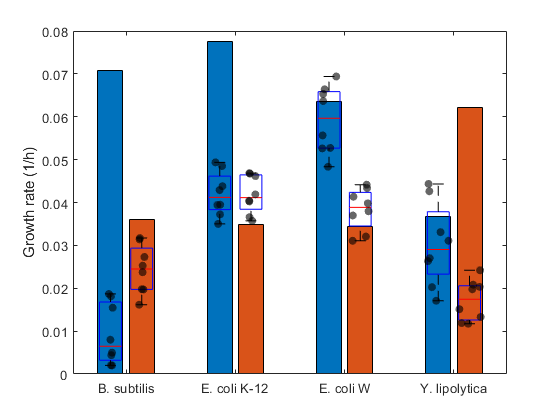

val=sort(horzcat(x1',x2'));
x=[1.02335462265022,0.988349509856046,0.981093778109534,1.00536889000141,1.00726762202390,1.01872123144545,1.01986645967575,0.977658877911296,1.01297566084189,1.01794519824171;0.999086159612356,0.978754824755511,0.979536061366517,0.985010791496149,1.01391433448524,0.995363978314577,1.01635208224383,0.982398398386402,1.01164573836811,0.982494587289869;1.01692151718817,1.00226834741586,1.02305840676997,0.978774763114767,1.02169166959690,0.992971204140524,0.978346519780334,1.02329667485952,1.00747264526993,0.996030841095801;1.00482203636179,0.992354421885306,0.985881331144653,0.976892064825271,0.982671271596351,0.993669111903245,1.01884075110753,0.997057415600578,1.00688849018045,0.994390334094638;1.01685980149586,1.01331586371854,0.981279213427960,0.979633056934570,1.00801591410816,0.993883519219494,0.980389617365114,1.00619054816540,1.00608002837266,1.02058137176000;1.00530658796947,0.999267278587580,1.00383704942358,1.02410505814116,1.00092841436309,0.992435086251361,1.02414371574106,1.02460051413362,1.01980787172814,1.01207901713850;1.00823683164575,1.01166813484128,0.996795815734447,0.994981608706989,0.985894560603085,1.01908149973950,1.02210348320354,1.02244774299356,0.980322141608115,0.977898766248371;0.983186197796184,1.00137369603708,0.978487404613133,0.975507287504612,0.979584001252091,1.00537175080825,0.977804274799491,1.00790502149938,1.00379099471440,0.978691768023167];
for i=1:numel(ExperimentalC)
    if i<5
        f1=scatter(x(:,i)*val(i),Dots(:,i),'k','filled');f1.MarkerFaceAlpha = 0.6; hold on 
    else
        n=i-4;
        f1=scatter(x(:,i)*val(i),Dots2(:,n),'k','filled');f1.MarkerFaceAlpha = 0.6; hold on 
    end
end
hold off
box on
ylabel('Growth rate (1/h)')

% CyanoGr=[0.0539018677457700;0.0412926720536526;0.0707901123230683;0.0775740479548660;0.0634696755994358;0.0368106846432872];
% bar(CyanoGr)
% somenames={'Wild type'; 'cscB'; 'B. subtilis';'E. coli K-12';'E. coli W';'Y. lipolytica' };
% set(gca,'xticklabel',somenames)
% 
% 
% 
% AllGr=[0.0539018677457700,0.0412926720536526,0;0.0150635249303998,0.0707901123230680,0.0608822682514390;0,0.0775740479548660,0.0210535307708170;0.0380641908048417,0.0634696755994360,0.0343647085552430;0.0456470086745339,0.0482842824964500,0.0492774928004560];
% bar(AllGr)
% somenames={'S. elongatus'; 'B. subtilis';'E. coli K-12';'E. coli W';'Y. lipolytica' };
% set(gca,'xticklabel',somenames)
% %breakyaxis([0.09 0.36])

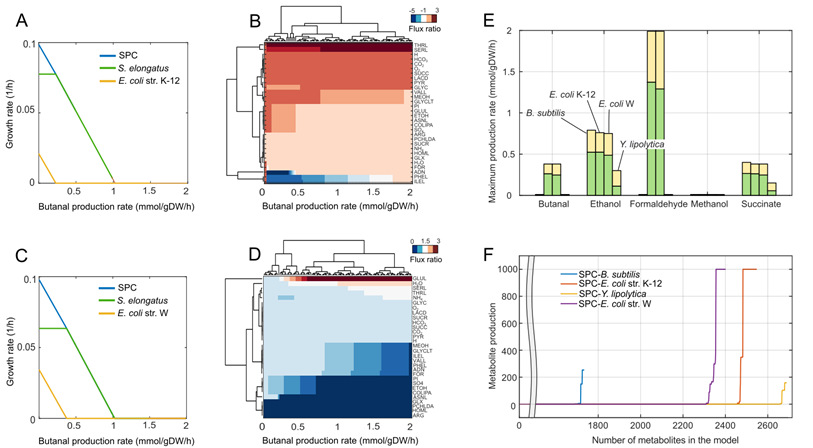

**Figure 2. Production of organic chemicals and other molecules is feasible in synthetic phototrophic communities (SPC). **

(A) Predicted growth rates for the SPC composed by *E. coli *K-12 and *S. elongatus*. The butanal production rate was constrained in all models from 0-2 mmol/gDW/h in 200 steps (Data S1). The overall growth rate of the community (blue line) and each member (heterotroph in yellow and phototroph in green) were simulated. Only the SPC containing *E. coli* strains were able to synthesize butanal without lethal phenotypes for the community members (see Figure S1). Simulations show that at higher butanal production rates the heterotroph will be outcompeted first and them the phototroph.

(B) Predicted tuning of the metabolic exchange associated with butanal secretion by the pair *E. coli *K-12 and *S. elongatus*. The exchange of isoleucine (ILEL), phenylalanine (PHEL), serine (SERL), and threonine (THRL) is highly activated. The metabolic exchange of all SPC is given in Figure S2. Annotation of all metabolites is given in Data S1.

(C) Growth rates profile of the community composed by *E. coli *W and *S. elongatus *while butanal production, the shared metabolites are shown in (D). 

(E) Overall production capabilities for butanal, ethanol, formaldehyde, methanol, and succinate. The bar plot shows the maximum production rate achieved by all microbial communities. The initial abundance of *S. elongatus* is given in green and for the heterotrophs in yellow. Microbial communities having *E. coli* strains showed high production potential for all tested metabolites, especially in the synthesis of formaldehyde.

(F) Attainable production capabilities were evaluated for all SPC by iteratively simulate the synthesis of all metabolites in the models alongside the community growth was constrained.

%Figure 2
for i=1:numel(modelsCo)
    FBA_Co{i}=optimizeCbModel(modelsCo{i,1});
    BOF=find(modelsCo{i,1}.c);
    SP_Co{i,1}=FBA_Co{i}.y;
    GrCo(i,1)= FBA_Co{i}.x(BOF(1));
    GrCo(i,2)= FBA_Co{i}.x(BOF(2));
end
for i=1:numel(modelsCo)
    FBA=optimizeCbModel(modelsCo{i,1});
    BOF=find(modelsCo{i,1}.c);
    SP_Co{i,1}=FBA.y;
    GrCo(i,1)= FBA.x(BOF(1));
    GrCo(i,2)= FBA.x(BOF(2));
end
model=modelCo2{2,1};
Rxn=strmatch('DM_',model.rxns)
A=optimizeCbModel(model)
BOF=find(model.c)
A.x(BOF)
model.lb(BOF(1))=A.x(BOF(1))
model.ub(BOF(1))=A.x(BOF(1))
model.lb(BOF(2))=A.x(BOF(2))
model.ub(BOF(2))=A.x(BOF(2))
model.c(BOF)=0;

for i=1:numel(Rxn)
    model2=model;
    model2.c(Rxn(i))=1;   
    BOF=find(model2.c);
    A=optimizeCbModel(model2);
    Results(i,1)=A.x(BOF)
end

for j=1:numel(modelCo2)
    model=modelCo2{j,1};
    A=optimizeCbModel(model)
    BOF=find(model.c)
    A.x(BOF)
    model.lb(BOF(1))=A.x(BOF(1))
    model.ub(BOF(1))=A.x(BOF(1))
    model.lb(BOF(2))=A.x(BOF(2))
    model.ub(BOF(2))=A.x(BOF(2))
    model.c(BOF)=0;

    for i=1:numel(model.mets)
            model2 = addDemandReaction(model, model.mets{i});
            model2.c(numel(model2.rxns))=1;   
            BOF=find(model2.c);
            A=optimizeCbModel(model2,'max','one');
                if A.f~=0
                Results(i,j)=A.x(BOF);
                else
                    Results(i,j)=0;
                end
    end
end
Results=[0,0,0,0;1.26599009053763e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,49.7133332550833,0;0,0,0,0;0,0,0,0;0,0,0,0;1.32877465974790e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,999.999998237414,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,999.999064128538,0;0,0,0,0;0,0,0,0;0,0,999.999978356841,0;0,0,23.6516604686135,0;0,0,0,0;0,0,0,0;0,0,999.987611110449,0;0,0,0,95.6358107792506;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,5.93053878053315;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.38851215247815e-10,0,0,0;0,0,999.999669640339,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,999.978640607549,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;3.04221481339795e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,158.508021492685;0,0,0,0;0,0,0,0;0,0,0,0;0,1.55148095909732e-07,0,0;0,47.0331358808560,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,999.999956142454,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,999.924111715654,0;0,0,0,1.10787823359715e-10;0,0,999.999979499295,0;0,0,0,0;0,0,148.851013961116,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,297.702027922112,0;0,0,0,0;0,0,0,0;0,0,1000,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,999.999669640339,0;0,0,0,0;0,0,379.073065051336,0;0,0,7.03751827231146,0;0,0,0,0;0,0,999.999991812412,0;0,0,1000,0;0,0,0,0;0,21.5933308299255,0,0;0,0,0,0;0,0,0,158.508021492687;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.46717034571727e-10,0,0,0;1.40825517913612e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.10527823005135e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;4.61092053427592e-10,0,0,0;2.08461990724995e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.10900410382753e-10,0,0,0;1.15272898865149e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;5.63608965054030e-10,0,0,0;0,0,0,-7.53647144691172e-13;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;2.19476894991466e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,158.508021492693;0,0,0,103.114993539491;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0.0237731175156983,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,103.118527488261;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.68155247775315e-05,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,999.999596227080,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0.0100000000000000,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,7.03751827230963,0;0,0,0,0;0,0,0,0;0,999.999596227080,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,999.999997882330,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,103.128865051273;0,0,0,0;0,0,0,0;1.57317213075880e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,95.6358107792482;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,158.508021492687;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;3.94495811336192e-10,0,0,0;0,3.47531852009175e-05,0,0;0,0,0,0;0,0,0,0;0.000698020309857678,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0.0131554278725259;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.49592144227384e-10,0,0,0;0,0,0,0;0,0,0,0;1.39242190694278e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,297.702027922109,0;0,0,148.851013961094,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,1000,0,0;0,1000,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.63176659684350e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;2.22264540106210e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;149.214523168015,0,0,0;0,0,0,0;149.214523167716,0,0,0;0,0,0,0;4.98232891719636,0,0,0;253.036169048246,0,0,0;0,0,165.721276325649,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,999.924111715654,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,1000,0,0;0,347.637651159752,0,5.93053878054072;0,0,0,0;0,0,0,0;0,0,0,0;1.48680212239127e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.14352929035666e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.24937773885239e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,165.721276325649,0;0,0,0,0;1.54166360233354e-10,0,7.03751827231292,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;2.47715903345380e-10,0,0,0;0,0,0,0;0,0,148.851013961061,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,999.984858034947,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.52166779177065e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;2.32830643653870e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,3.47531703463712e-05,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0.0223954665469144,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,999.998936350200,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.41162677901041e-10,0,0,0;0.000900000000000000,0,0,0;0,999.999946396333,0,0;0,0,0,0;0,0,0,0;0.000160000000000000,0,0,0;0,0,0,0;0,999.999989992948,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.79853999570988,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,999.999999995853,0,0;0,0,0,0;0,0,0,0;5.90238816782699,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,19.3812811129898,0,0;1.76000000000000,999.999974943583,0,0;1.76000000000000,0,0,0;1.76000000000000,0,0,0;0,0,0,0;0,7.50000000000000,999.999999995911,0;0,7.50000000000000,999.999999995911,0;253.036169047924,0,0,0;0,347.637651159752,0,0;0,348.508923468424,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.23360559180913e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;2.87501552079239e-10,0,0,0;4.83175333076957e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;4.87596904482162,0,0,0;0,0,0,0;0,0,0,0;1.10681422360592e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;2.43798452252434,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.62532301498797,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,999.910299804754,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,181.268260130416,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,103.128865051272;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.19126764008826e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.27853058001781e-10,0,0,0;0,0,0,0;0,0,0,0;4.98232891719636,0,0,0;4.98232891719636,0,0,1.10787823359715e-10;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,1.10787823359715e-10;0,0,0,0;0,0,0,0;0,0,0,1.10843689153477e-10;0,0,0,0;0,0,0,0;0,0,0,0.0131554278725259;0,0,0,0;0,1000,0,0;0,150.123464952520,0,0;0,89.1693587030252,0,0;1.64755313558640e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;2.32830643653870e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,1000,0,0;0,0,1.26939351198872e-07,0;0,0,0,0;0,999.975008015700,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,999.999669640339,0;0,0,0,0;0,0,0,0;0,0,196.014994198325,0;0,0,0,0;0,0,0,0;0,0,0.0100000000000000,0;0,0,0.0100000000000000,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;2.49116445859818,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,1.10787823359715e-10;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,999.999669640339,0;0,0,0,0;0,0,0,0.0131554278725259;1.31000296547945e-10,0,0,0;0,0,999.999998237414,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.02185114536635e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,1000,0,0;7.70000000000000e-05,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.32480804104773e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,223.107340005508,0;149.214523167549,0,0,0;4.98232891719636,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.79853999570988,0,0,0;0,0,0,0;1.62748375540089e-10,0,88.5649138447794,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;253.036169048143,0,0,0;0,0,0,0;0,0,0,0;0.0223954665469144,0,0,0;0,0,0,0;253.036169048211,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.62532301488369,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,999.999973547250,0,0;0,0,0,0;0,0,0,0;4.98232891719636,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;4.87596904519572,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;3.00000000000000e-05,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0.000698020309857678,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.13882452079661e-10,0,2.84344146685472e-05,0;0,0,2.84344146685472e-05,0;0,0,0,0;0,0,0,0;0.0237731175156983,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0.0459999039760624;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,1.79853999261354;0,0,0,0;0,0,0,0;0,0,0,0;253.036169048095,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0.0131554278725258;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.76000000000000,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;253.036169048211,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;149.214523167477,0,0,0;253.036169048143,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.68155247775315e-05,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0.000900000000000000,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,1000,0;0,0,0,0;0,0,0,0;0,0,0,0;4.98232891719636,0,0,0;0,0,0,0;0,0,0,0;0,0,1000,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.26684107648600e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,22.7163036647622,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;253.036169047891,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,1.10787823359715e-10;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,7.50000000000000,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0.000698020309857678,0,0,0;7.70000000000000e-05,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,103.128865051273;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.52238642684240e-10,0,0,0;0,0,0,0;1.76000000000000,0,0,0;0,0,0,158.508021492697;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;2.43798452250806,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;149.214523167385,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.88732288168272e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;253.036169048002,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0.000160000000000000,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.29647248665876e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.40987499452905e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,88.5649138447821,0;0,0,0,0;0,0,0,0;0,0,0,0;149.214523167419,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;2.17162502939484e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.22856252948722e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;5.90238816735426,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;253.036169048136,0,0,0;0,0,0,0;0,0,999.987611110449,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;149.214523167867,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,103.128865051262;0,0,0,0;0,0,0,103.128865051270;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.68155247775315e-05,0,0,0;7.70000000000000e-05,0,0,0;4.98232891719636,0,0,0;0,0,0,0;0.0237731175156983,0,0,0;5.90238816793481,0,0,0;0,0,0,0;0,0,0,0;0.000900000000000000,0,0,0;1.38755007483837e-10,0,0,0;0.0223954665469144,0,0,0;0,0,0,0;0,999.999596227080,0,0;3.00000000000000e-05,0,0,0;0,0.0100000000000000,0,0;1.76000000000000,0,0,0;0.000698020309857678,0,0,0;0.000160000000000000,0,0,0;0,0,0,0;0,0,0,0;4.87596904504907,999.999596227080,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.79853999570988,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,999.999997882330,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,999.999064128539,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,999.999956142454,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,999.999991812412,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,999.999979499295,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,7.03751827231686,0;0,0,7.03751827230966,0;0,1000,7.03751827230493,0;2.26290010750421e-10,1000,7.03751827231281,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,1000,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,999.984858034947,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,999.998936350200,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,999.999946396333,0,103.128865051269;0,0,165.721276325649,0.0131554278725259;0,999.999989992948,0,0;0,0,0,0;0,0,0,0;0,0,0,1.79853999261354;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0.0293041045309463;0,999.999999995853,0,0;0,0,0,158.508021492689;0,19.3812811129941,0,0;0,999.999974943583,0,0;0,0,0,0;0,0,0,0;0,7.50000000000000,0,0;0,7.50000000000000,0,0;0,0,0,0;0,0,92.2661338202472,0;0,0,1000,0;0,0,0,0;0,0,0,0;0,0,150.192428078011,0;0,347.637651159753,1000,0;0,0,1000,0;0,0,0,0;0,0,0,0;0,0,0,0.0131554278725258;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,1000,0;1.76000000000000,0,0,0;0,0,999.978640607549,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;3.94495811336192e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,3.00000000000000e-05;0,0,0,0;0,0,0,0;0,999.910299804750,0,0;0,0,0,0;0,0,0,0.000900563519411829;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,158.508021492686;0,0,0,0;0,0,0,0;0,0,1000,0;0,0,1000,0;0,0,0,0;0,0,0,0.0240000000000000;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,1000,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,1000,0,0;0,0,0,0;0,0,0,0;0,999.975008015700,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,1000,0,0;0,0,0,0;0,0,999.999978356841,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,999.999973547250,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,1.76000000000000;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,158.508021492689;0,1000,0,0;0,118.494426855679,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,999.999999995853,0,0;0,0,0,0;0,0,0,103.128865051273;0,0,0,0;0,0,0,0;0,0,2.84344143599052e-05,0;0,0,0,0;0,0,0,1.66823823603260e-05;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0.000900000000000000;0,0,0,0;0,0,0,0;0,999.998936350200,0,0;0,0,0,0;0,347.637651159751,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,1.41537376586742e-05,0;0,0,0,0.0131554278725259;0,0,0,0;0,999.975008015700,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,999.910299804757,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,770.031746717331,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,349.987570497690,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,999.999596227080,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,158.508021492688;0,0,0,0;0,0,0,0.0459999039760624;0,0,0,0;0,0,0,0;0,999.999974943583,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0.000900563519411829;0,0,0,7.70000000000000e-05;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,1.76000000000000;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,148.851013961033,0;0,0,118.272399989573,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,999.999999995911,0;0,0,0,103.128865051272;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,7.50000000000000,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,297.702027922116,0;0,0,0,0;0,0,0,0;0,0,999.999064128538,0;0,0,0,0;0,0,165.721276325650,0;0,347.637651159751,0,0;0,0,0,158.508021492685;0,0,0,0;0,0,0,0;0,0,176.746193837368,0;0,0,0,0;0,0,0,0;0,0,0,0;0,1000,0,0;0,0,0,0.000160000000000000;0,0,0,0;0,0,0,0;0,0,0,0;0,999.999997882330,0,0;0,0,0,0;0,0,0,0;0,0,999.978640607549,0;0,999.999946396333,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,103.128865051270;0,0,0,0;0,0,0,0;0,0,0,0;0,308.483666116123,999.924111715655,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,770.843559297270,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,165.721276325650,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,999.999669640339,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,999.999979499295,5.93053878054127;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,297.702027922176,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,347.637651159752,0,0;0,0,0,0;0,999.984858034947,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,999.999944173614,0,0;0,999.999973547250,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,7.03751827230933,0;0,0,0,0;0,0,0,0;0,0,0,0;0,7.50000000000000,0,0;0,0,0,0;0,0,0,1.66823823603260e-05;0,0,0,7.70000000000000e-05;0,0,0,0.0131554278725259;0,0,0,0;0,0,165.721276325650,0.0240000000000000;0,0,0,5.93053878053284;0,0,0,0;0,0,0,0;0,0,0,0.000900000000000000;0,0,0,0;0,0,0,0.0293041045309463;0,1000,0,0;0,0,148.851013961083,0;0,0,297.702027922116,3.00000000000000e-05;0,0,0,0.0459999039760624;0,0,0,1.76000000000000;0,0,0,0.000900563519411830;0,0,999.999998237414,0.000160000000000000;0,0,0,0;0,0,0,0;0,0,0,0;0,0,999.999956142454,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,347.637651159752,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,1.79853999261354;0,0,0,0;0,999.999989992948,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,308.808887669570,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,165.721276325646,0;0,0,0,0;0,0,999.987611110449,0;0,0,0,0;0,0,0,0;0,19.3812811129811,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,999.999944948493,0;0,0,999.999978356841,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,7.03751827231417,0;0,0,0,0;0,0,0,0;0,0,0,0;0,349.988212722840,0,0;0,0,0,0;0,0,320.479449170611,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,148.851013961058,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,999.999997882330,0,0;0,999.999973547250,0,0;0,999.975008015700,0,0;0,0,0,0;0,999.999596227080,0,0;0,19.3812811129825,165.721276325649,0;0,0,0,0;0,0,0,0;0,999.999946396333,0,0;0,0,0,0;0,999.998936350199,0,0;0,0,0,0;0,1000,0,0;0,0,999.999991812412,0;0,999.984858034947,0,0;0,7.50000000000000,0,0;0,999.999944173614,0,0;0,999.999989992948,0,0;0,999.999974943583,0,0;0,0,0,0;0,999.910299804752,0,0;0,0,0,0;0,0,0,0;0,999.999999995853,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,148.851013961060,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,7.03751827231590,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,297.702027921809,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0.0459999039760624;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,148.851013961059,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,999.999998237414,0;0,0,999.999978356841,0;0,0,999.978640607549,0;0,0,0,0;0,0,999.999669640339,0;0,0,7.03751827231365,0;0,0,0,0;0,0,0,0;0,0,999.999956142454,0;0,0,0,0;0,0,999.999064128539,0;0,0,0,0;0,0,1000,0;0,0,0,0;0,0,999.987611110449,0;0,0,7.03751827230493,0;0,0,999.999944948493,0;0,0,999.999991812412,0;0,0,999.999979499295,0;0,0,0,0;0,0,999.924111715656,0;0,0,0,0;0,0,0,0;0,0,999.999999995911,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,7.50000000000000,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,999.999596227080,0,0;0,0,0,0;0,999.984858034947,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,7.03751827231321,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,999.999669640339,0;0,0,0,0;0,0,999.987611110449,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0];



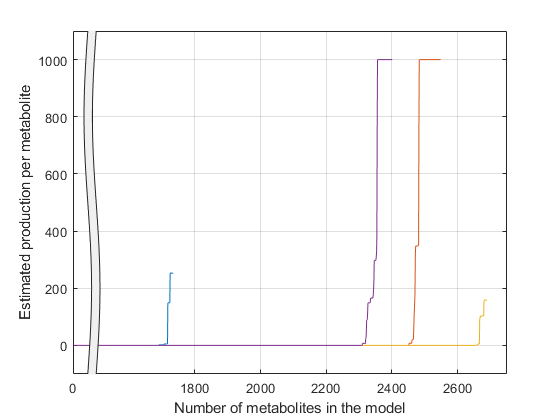

annotationAxes =   Axes with properties:

             XLim: [0 2750]
             YLim: [-100 1100]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ans = struct with fields:
            leftAxes: [1×1 Axes]
           rightAxes: [1×1 Axes]
           breakAxes: [1×1 Axes]
      annotationAxes: [1×1 Axes]
    invisibleObjects: [1×5 Graphics]


figure
plot(sort(Results(1:numel(modelCo2{1,1}.mets),1)))
hold on
plot(sort(Results(1:numel(modelCo2{2,1}.mets),2)))
plot(sort(Results(1:numel(modelCo2{3,1}.mets),4)))
plot(sort(Results(1:numel(modelCo2{4,1}.mets),3)))
axis([0 2750 -100 1100])
xlabel('Number of metabolites in the model');
ylabel('Estimated production per metabolite');
legend('\itB. subtilis','\itE. coli K-12','\itE. coli W','\itY. lipolytica');
grid on
BreakXAxis([45 1500])

numel(find(Results(:,1)>0));
numel(find(Results(:,2)>0));
numel(find(Results(:,3)>0));
numel(find(Results(:,4)>0));

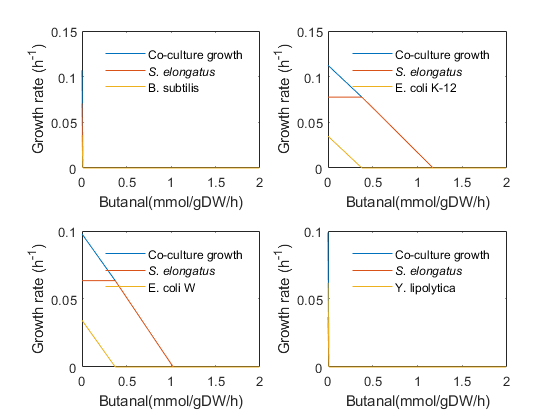

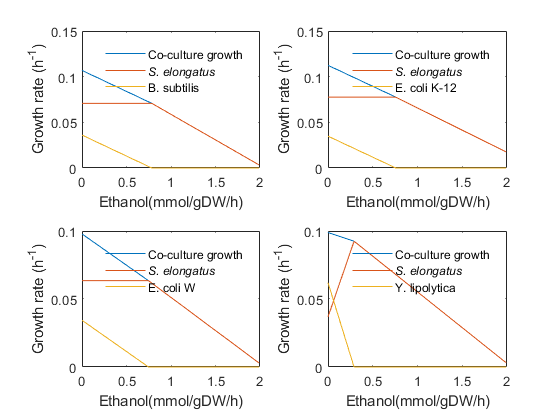

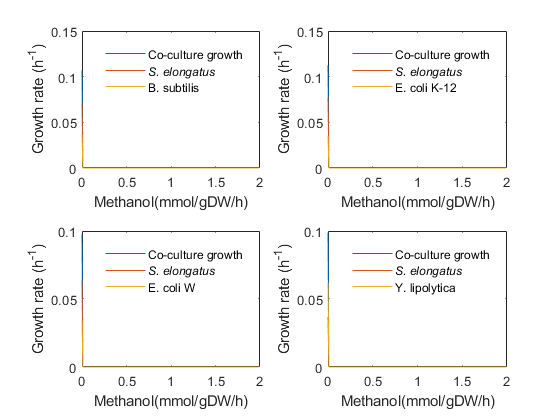

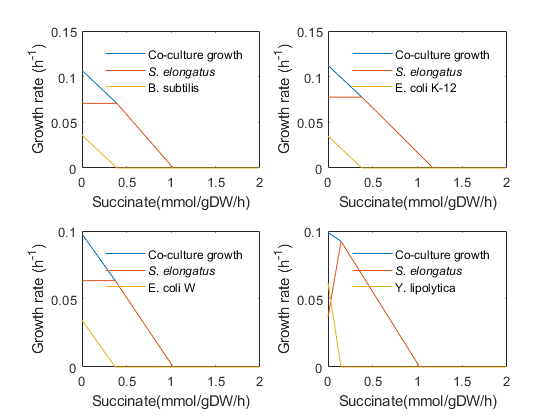


%Figure 2
%Estimating productivity
units={'(mmol/gDW/h)'};
  Enzymes2={'EX_4abutn_[smp]';'EX_etoh_[smp]';'EX_meoh_[smp]';'EX_succ_[smp]'};%
Enzymes={'Butanal';'Ethanol';'Methanol';'Succinate'};
somenames={'B. subtilis';'E. coli K-12';'E. coli W';'Y. lipolytica' };
mayaAuto(:)='';x(:)='';mayaAuto1=[];mayaAuto2=[];FBAs=[];
FBA={};

%Generating all plots
for k=1:numel(Enzymes2)
    figure
    for j=1:numel(modelCo2)
        model=modelCo2{j,1};
        BOFs=find(model.c);
        Solu=optimizeCbModel(model,'max');       
         FBAs=[];
        for i=1:200
            valor=(i-1)/100;
        model=changeRxnBounds(model,Enzymes2{k},valor,'b'); 
        solutionLna = optimizeCbModel(model,'max');
        FBAs=horzcat(FBAs,solutionLna.x);
        mayaAuto(i)=solutionLna.f;
            if mayaAuto(i)~=0
            mayaAuto1(i)=solutionLna.x(BOFs(1,1));
            mayaAuto2(i)=solutionLna.x(BOFs(2,1));
            else
               mayaAuto1(i)=0;
               mayaAuto2(i)=0;
            end          
        x(i)=valor;
        end
        FBA{j}=FBAs;
        subplot(numel(modelCo2)/2,2,j)
        plot(x,mayaAuto)
        hold on
        plot(x,mayaAuto1)
        plot(x,mayaAuto2)
        hold off
       %axis([0.0 4 -0.000 0.15])
        xlabel(strcat(Enzymes{k},units));
        ylabel('Growth rate (h^-^1)');
        mayaAuto(:)='';x(:)='';mayaAuto1(:)='';mayaAuto2(:)='';
    legend('Co-culture growth','\itS. elongatus' ,somenames{j})
    legend('boxoff')
    end
end

%Figure S2
[modelCo2{1,1},SPM_A1Bs,SPM_D1Bs, Un_DBs, Un_ABs] = sharedPoolCM(modelCo2{1,1},1);
[modelCo2{2,1},SPM_A1Ec,SPM_D1Ec, Un_DEc, Un_AEc] = sharedPoolCM(modelCo2{2,1},1);
[modelCo2{3,1},SPM_A1EcW,SPM_D1EcW, Un_DEcW, Un_AEcW] = sharedPoolCM(modelCo2{3,1},1);
[modelCo2{4,1},SPM_A1Yl,SPM_D1Yl, Un_DYl, Un_AYl] = sharedPoolCM(modelCo2{4,1},0);


[ExchangeCo,DataCo] = exchangeCombinedModel(modelCo2{1,1});
[ExchangeA,DataA] = exchangeSingleModel(SingleM{1,1});
[ExchangeB,DataB] = exchangeSingleModel(SingleM{6,1});
%modelCo2 contains all the models with open exchange reactions
for i=1:numel(modelCo2)
   FBA=optimizeCbModel(modelCo2{i,1});
   BOF=find(modelCo2{i,1}.c);
   GrCo2(i,1)= FBA.x(BOF(1));
   GrCo2(i,2)= FBA.x(BOF(2));
end



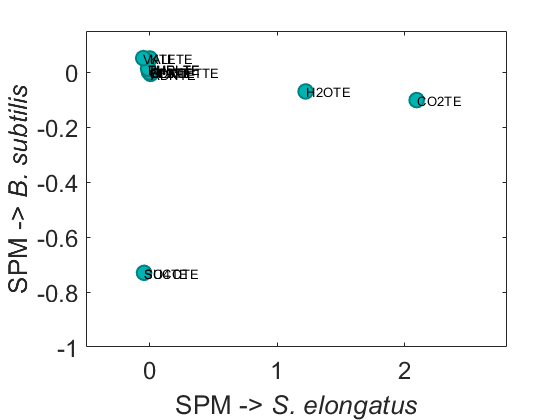

%%
%Generating scatter plots
%Case 1 Se-Bs
SPM_D1=SPM_D1Bs;
SPM_D1.Flux(7) = -0.070;
SPM_D1.Flux(9) = 0.949;
SPM_D1.Rxn(14) = -0.045;
SPM_D1.Flux(14) = -0.73;
SPM_D1.Flux(5)=9.753205432020080e-05;
SPM_D1(12,:) = [];
SPM_D1Bs=SPM_D1;
SPMss={};
        for i=1:height(SPM_D1)
            String=SPM_D1.Full_Name(i,1);
            SPMss{i,1}=upper(String{1,1}(1:end-3));
        end
        b=SPMss;
        DAta=SPM_D1.Rxn;
        DAta2=SPM_D1.Flux;
        plot(DAta,DAta2,'O','MarkerSize',11,'MarkerEdgeColor',[0 .5 .5],...
                      'MarkerFaceColor',[0 .7 .7],...
                      'LineWidth',1.5)
                 set(gca,'FontSize',18);
        xlabel('SPM -> \it{S. elongatus}')
        ylabel('SPM -> \it{B. subtilis}')
        text(DAta,DAta2,b,'FontSize',10)   
         axis([-0.5 2.8 -1 0.15])

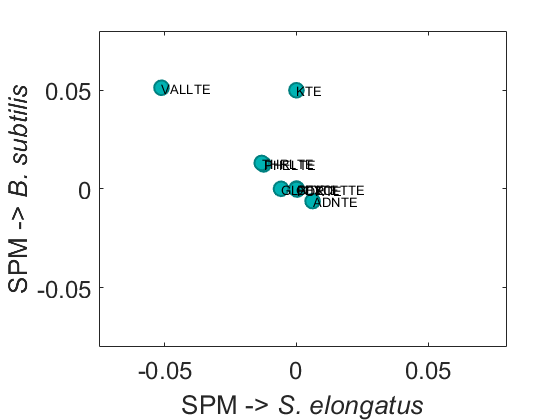

        %Deeper view SPM plot
        plot(DAta,DAta2,'O','MarkerSize',11,'MarkerEdgeColor',[0 .5 .5],...
                      'MarkerFaceColor',[0 .7 .7],...
                      'LineWidth',1.5)
                 set(gca,'FontSize',18);
        xlabel('SPM -> \it{S. elongatus}')
        ylabel('SPM -> \it{B. subtilis}')
        text(DAta,DAta2,b,'FontSize',10)
        axis([-0.075 0.08 -0.08 0.08])%

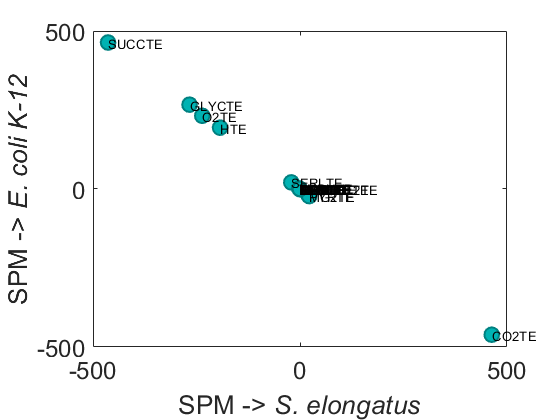

%Case 2 Se-E. coli K12
        SPM_D1=SPM_D1Ec;
SPM_D1.Rxn(17) = 21.2;
SPM_D1.Flux(17) = -21.0;
SPM_D1.Rxn(21) = 22.4;
SPM_D1.Flux(21) = -22.4;
SPM_D1.Flux(22) = 21;
SPM_D1.Rxn(22) = -21;
SPM_D1Ec=SPM_D1;

SPMss={};
        for i=1:height(SPM_D1)
            String=SPM_D1.Full_Name(i,1);
            SPMss{i,1}=upper(String{1,1}(1:end-3));
        end
        b=SPMss;
        DAta=SPM_D1.Rxn;
        DAta2=SPM_D1.Flux;
        plot(DAta,DAta2,'O','MarkerSize',11,'MarkerEdgeColor',[0 .5 .5],...
                      'MarkerFaceColor',[0 .7 .7],...
                      'LineWidth',1.5)
                 set(gca,'FontSize',18);
        xlabel('SPM -> \it{S. elongatus}')
        ylabel('SPM -> \it{E. coli K-12}')
        text(DAta,DAta2,b,'FontSize',10)    

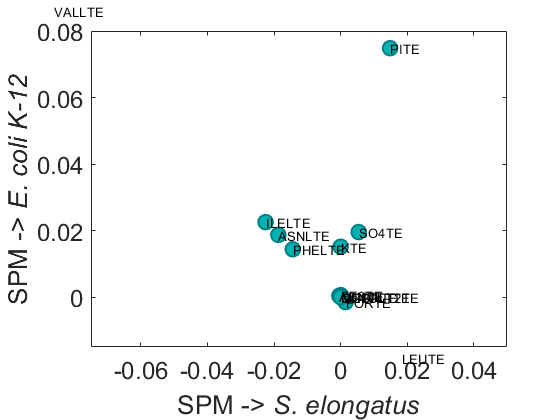

        %Deeper view SPM plot
        plot(DAta,DAta2,'O','MarkerSize',11,'MarkerEdgeColor',[0 .5 .5],...
                      'MarkerFaceColor',[0 .7 .7],...
                      'LineWidth',1.5)
                 set(gca,'FontSize',18);
        xlabel('SPM -> \it{S. elongatus}')
        ylabel('SPM -> \it{E. coli K-12}')
        text(DAta,DAta2,b,'FontSize',10)
        axis([-0.075 0.05 -0.015 0.08])

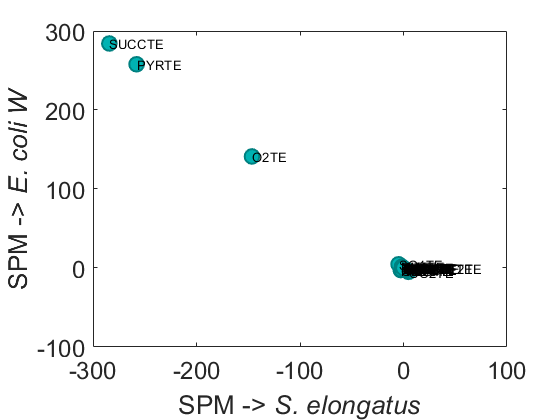

%Case 2 Se-E. coli W        
SPM_D1=SPM_D1EcW;
SPM_D1.Rxn(3) = 4.85;
SPM_D1.Flux(3) = -4.83;
SPM_D1.Rxn(9) = -2.63;
SPM_D1.Flux(9) = -2.63;
SPM_D1.Rxn(11) = -2.08;
SPM_D1.Flux(11) = -2.10;
SPM_D1.Rxn(16) = -2.47;
SPM_D1.Flux(16) = 2.36;
SPM_D1.Rxn(19) = -2.59;
SPM_D1.Flux(19) = 2.59;
SPM_D1.Rxn(22) = -4.75;
SPM_D1.Flux(22) = 4.75;
SPM_D1.Flux(14) = 1.269393123948248e-07;
SPM_D1EcW=SPM_D1;

        SPMss={};
        for i=1:height(SPM_D1)
            String=SPM_D1.Full_Name(i,1);
            SPMss{i,1}=upper(String{1,1}(1:end-3));
        end
        b=SPMss;
        DAta=SPM_D1.Rxn;
        DAta2=SPM_D1.Flux;
        plot(DAta,DAta2,'O','MarkerSize',11,'MarkerEdgeColor',[0 .5 .5],...
                      'MarkerFaceColor',[0 .7 .7],...
                      'LineWidth',1.5)
                 set(gca,'FontSize',18);
        xlabel('SPM -> \it{S. elongatus}')
        ylabel('SPM -> \it{E. coli W}')
        text(DAta,DAta2,b,'FontSize',10)    

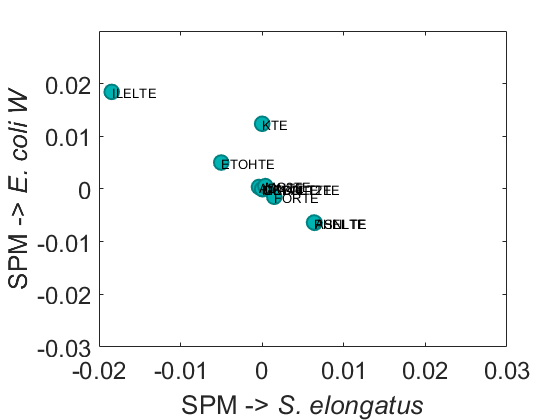

        %Deeper view SPM plot
        plot(DAta,DAta2,'O','MarkerSize',11,'MarkerEdgeColor',[0 .5 .5],...
                      'MarkerFaceColor',[0 .7 .7],...
                      'LineWidth',1.5)
                 set(gca,'FontSize',18);
        xlabel('SPM -> \it{S. elongatus}')
        ylabel('SPM -> \it{E. coli W}')
        text(DAta,DAta2,b,'FontSize',10)
        axis([-0.02 0.03 -0.03 0.03])        

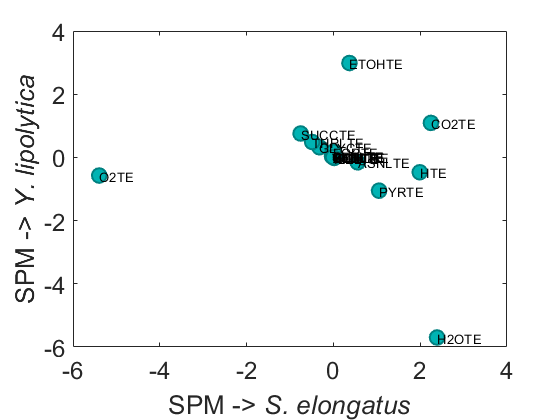


        %Case 2 Se-Y. lipolytica
        SPM_D1=SPM_D1Yl;
SPM_D1.Flux(3) = -0.1561;
SPM_D1.Flux(14) = 0.1820;
SPM_D1.Flux(19) = -0.5739;
SPM_D1.Flux(16) = -0.4699;
SPM_D1Yl=SPM_D1;
save('SPM_D1Yl','SPM_D1Yl')

        SPMss={};
        for i=1:height(SPM_D1)
            String=SPM_D1.Full_Name(i,1);
            SPMss{i,1}=upper(String{1,1}(1:end-3));
        end
        b=SPMss;
        DAta=SPM_D1.Rxn;
        DAta2=SPM_D1.Flux;
        plot(DAta,DAta2,'O','MarkerSize',11,'MarkerEdgeColor',[0 .5 .5],...
                      'MarkerFaceColor',[0 .7 .7],...
                      'LineWidth',1.5)
                 set(gca,'FontSize',18);
        xlabel('SPM -> \it{S. elongatus}')
        ylabel('SPM -> \it{Y. lipolytica}')
        text(DAta,DAta2,b,'FontSize',10)    

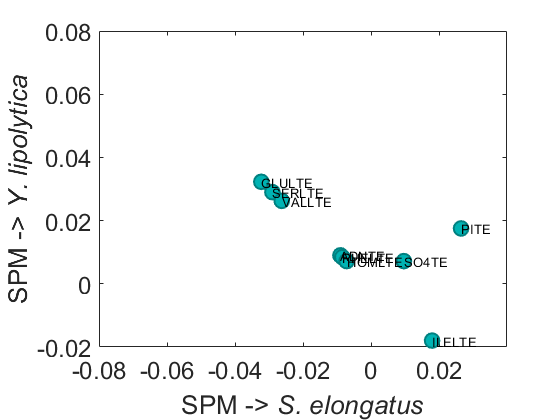

        %Deeper view SPM plot
        plot(DAta,DAta2,'O','MarkerSize',11,'MarkerEdgeColor',[0 .5 .5],...
                      'MarkerFaceColor',[0 .7 .7],...
                      'LineWidth',1.5)
                 set(gca,'FontSize',18);
        xlabel('SPM -> \it{S. elongatus}')
        ylabel('SPM -> \it{Y. lipolytica}')
        text(DAta,DAta2,b,'FontSize',10)
        axis([-0.08 0.04 -0.02 0.08])

## 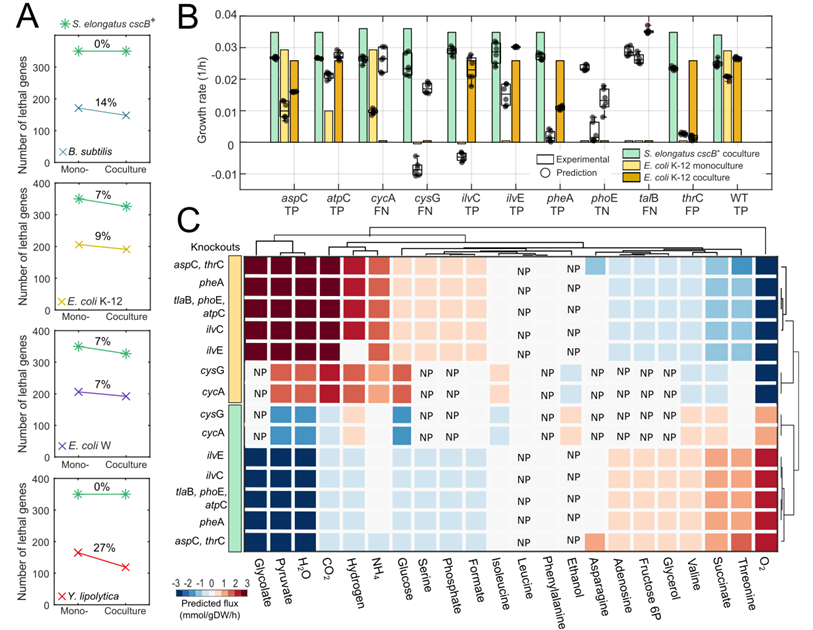

**Figure 3. Community fitness fills up for lethal phenotypic traits by tuning metabolic exchange.**

(A) Resistance analysis to lethal phenotypes across community members. The percentage of knockouts (KOs) with lethal phenotypes was estimated for both community members using the difference of lethal KOs among monoculture and coculture conditions. The percentage reduction is shown for *S. elongatus* and for the heterotrophs. The communities can reduce their total lethal phenotypic outcomes by 5-9%. However, the heterotrophic partner benefited disproportionately reducing the number of lethal traits by at least 7% for *E. coli* W and up to 27% for *Y. lipolytica*. The percentage of lethality reduction was determined using the number of genes that are lethal in monoculture vs coculture. The complete dataset is given in Table S3. 

(B) Six *E. coli* K-12 mutant strains with lethal phenotypes (*ilv*C, *cys*G, *ilv*E, *phe*A, *pho*E, *thr*C) and four with nonlethal phenotypes (*asp*C, *cyc*A, *tal*B, *atp*C) were experimentally tested under monoculture and coculture conditions. Predicted growth phenotypes are shown with bars and experimental results with boxplots. In boxplots the central mark indicates the median, and the bottom and top edges of the box indicate the 25th and 75th percentiles, respectively.  Benchmarking of the models are given as true positive (TP), true negative (TN), false positive (FP), false negative (FN). 

(C) Predicted metabolic exchange shifts in accordance with the KO studied. Complete-linkage clustering shows metabolic exchange associations by genes (vertically) and metabolites (horizontally). The effect of each KO is shown for both community members. Flux distributions were normalized by using the flux distribution obtained under wild type conditions for both members. Predicted metabolic exchange of *tal*B, *pho*E, and *atp*C knockouts is represented in one row as the shifts were identical. Similarly, results were found for the metabolic exchange of KOs *asp*C and *thr*C. NP stands for metabolite not predicted to by exchange under certain condition.  

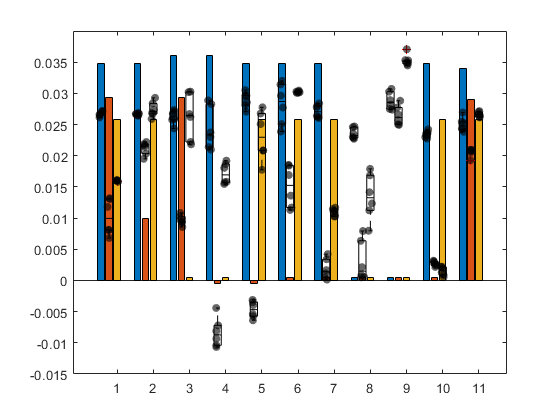

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

Results2=[0.0348484100000000,0.0293049140000000,0.0258580160000000;0.0348484100000000,0.00993906000000000,0.0258580160000000;0.0360199626666667,0.0293049140000000,0.0005;0.0360199626666667,-0.0005,0.0005;0.0348484100000000,-0.0005,0.0258580160000000;0.0348484100000000,0.0005,0.0258580160000000;0.0348484100000000,0.0005,0.0258580160000000;0.0005,0.0005,0.0005;0.0005,0.0005,0.0005;0.0348484100000000,0.0005,0.0258580160000000;0.0340000000000000,0.0290000000000000,0.0258666666666667];
figure
bar(Results2)

hold on
GenesNames={'pheA','ilvC','talB','wt','atpC','thrC','aspC','cycA','cysG','ilvE','phoE'};
[B,I] = sort(GenesNames);
ExpKO=[0.0271092210000000,0.0304680230000000,0.0290825720000000,0.0260320870000000,0.0265773320000000,0.0240306790000000,0.0266432320000000,0.0265675330000000,0.0243228690000000,0.0281270420000000,0.0241059390000000;0.00244385100000000,-0.00599012400000000,0.0269534260000000,0.0200000000000000,0.0196929400000000,0.00271229600000000,0.0100523610000000,0.00942884100000000,-0.00765366600000000,0.0150132440000000,0.00467491200000000;0.0109601030000000,0.0230636820000000,0.0355460090000000,0.0262693410000000,0.0275035080000000,0.00138633900000000,0.0159683850000000,0.0264725850000000,0.0174673710000000,0.0302572090000000,0.0140000000000000];
ExpKOError=[0.00133738300000000,0.00386047900000000,0.00186766700000000,0.00319858500000000,0.000388686000000000,0.00133738300000000,0.000999152000000000,0.00262191100000000,0.00464431700000000,0.00512174200000000,0.00270173000000000;0.00276842900000000,0.00288693300000000,0.00202290200000000,0.000950000000000000,0.00327275600000000,0.000955143000000000,0.00477469400000000,0.00229971800000000,0.00350000000000000,0.00375433300000000,0.00450000000000000;0.00158059600000000,0.00537640200000000,0.00206927200000000,0.000930608000000000,0.00191561700000000,0.000955143000000000,0.000154774000000000,0.00465949800000000,0.00223975700000000,0.000460618000000000,0.00602954200000000];
ExpKO=ExpKO';
ExpKOError=ExpKOError';
ExpKO=ExpKO(I,:);
ExpKOError=ExpKOError(I,:);
ngroups = size(ExpKO, 1);
nbars = size(ExpKO, 2);
groupwidth = min(0.8, nbars/(nbars + 1.5));
Dots=[0.0271939241458080,0.0268539318688571,0.0257736188159274,0.0237401684685870,0.0281092613425984,0.0238848380728971,0.0279952061147702,0.0228619481488816,0.0302684397598444,0.0235025610691598,0.0254438217469803,0.00810036529797215,0.0195005965581225,0.0108269379727444,-0.00811173373608697,-0.00311706978809418,0.0116951936862597,0.00422556448708737,0.000559676214832474,0.0256952250051390,0.00316461426487138,0.0207735218568494,0.0159995198776139,0.0268396506533882,0.0218302211089332,0.0158201778029040,0.0208371836733104,0.0304530311876368,0.0116834176058167,0.0168648575128801,0.0347264865942771,0.00197751503476940,0.0261978414407985;0.0270968739889818,0.0267539810683697,0.0243760332644946,0.0213817402382093,0.0296463603503798,0.0314172005290862,0.0260537991456426,0.0235200956515073,0.0307246306941265,0.0237364563844707,0.0243103346712721,0.0117989388234655,0.0214132308649170,0.0102378014136811,-0.00719421811238044,-0.00346353210729785,0.0135972591629384,0.000134742305459432,0.000517480474022074,0.0288170668708940,0.00242061988249119,0.0208973493524605,0.0159648596457359,0.0258899826518557,0.0266864472519464,0.0180546497628286,0.0267743166380142,0.0300712035993520,0.0102983943556836,0.0178912691165201,0.0352833366493841,0.00219268519143614,0.0261347176753645;0.0270535869694440,0.0264593691209744,0.0267324666742009,0.0230021647323333,0.0296504350497635,0.0277363489379919,0.0262196277230264,0.0246917505987629,0.0274948905344932,0.0234983499551232,0.0252546029610264,0.0130620846086631,0.0222064911689956,0.00963644844092416,-0.00934558333287333,-0.00573001087855200,0.0112917350672045,0.00165903954179510,0.000863542355603222,0.0250378957306169,0.00254608896014734,0.0209408906279255,0.0160285459363438,0.0283921645436657,0.0302101131342458,0.0192064810505628,0.0250817175662056,0.0301817678702123,0.0114481959585656,0.0112408456816853,0.0353284739391340,0.000881666899278291,0.0271556608608969;0.0261473594532786,0.0266700425551759,0.0273351737021619,0.0282785565945120,0.0270703850554631,0.0296428600807723,0.0263604229045048,0.0245979034193353,0.0281800755341270,0.0227564955201047,0.0269252081035685,0.00810841983387311,0.0203313087103511,0.00933533661315663,-0.0103914399348533,-0.00395332281752164,0.0169110991799354,0.00113284092302143,0.00213166661661334,0.0249406816923103,0.00291669751888133,0.0192936994137588,0.0158313569943262,0.0266950613386344,0.0302811688936469,0.0186673756320970,0.0277639723086195,0.0300906756620283,0.0111269100297746,0.0141499708037998,0.0349176764824142,0.00124028060431480,0.0266565043412480;0.0266464102096338,0.0264237905209230,0.0258911255832092,0.0209961064237877,0.0285400256495055,0.0250790014555868,0.0283866369608444,0.0227174314701391,0.0273810133210242,0.0229592279062615,0.0238408879434779,0.00681640617290688,0.0216753835177834,0.00856762556873093,-0.00440745419704608,-0.00540129143605067,0.0184212804095343,0.000518409204991385,0.00636113799997992,0.0277291634020474,0.00216965218827073,0.0209303562146556,0.0160208921344889,0.0273725982706964,0.0222201054313887,0.0157308392516998,0.0208378705364011,0.0302913713120395,0.0108969261429104,0.00797214082335473,0.0344793323372520,0.00219857461600894,0.0270417160077467;0.0264597302645560,0.0266877035092657,0.0270740103020427,0.0288766216779840,0.0305131761336649,0.0319986260436387,0.0277346456048263,0.0229901208417186,0.0289248323908738,0.0242355872923136,0.0242317705630097,0.0131778056501391,0.0218694446856198,0.00936080220356224,-0.0106690446963149,-0.00638689790238889,0.0185372739039232,0.00340180480640312,0.00793506685547115,0.0266074309711206,0.00304152514153571,0.0205555444728565,0.0161207471438863,0.0292856764789408,0.0262115755835731,0.0154671875030862,0.0177449119069101,0.0302648689436884,0.0102469321970512,0.0123596118503896,0.0370718516905088,0.000511995862504254,0.0264658941460280];
for i = 1:nbars
    x = (1:ngroups) - groupwidth/2 + (2*i-1) * groupwidth / (2*nbars);
   % errorbar(x, ExpKO(:,i), ExpKOError(:,i), '.');
    if i==1
    boxplot(Dots(:,1:11),'positions',x,'widths',0.2,'colors','k')
    elseif i==2
       boxplot(Dots(:,12:22),'positions',x,'widths',0.2,'colors','k')
    elseif i==3
        boxplot(Dots(:,23:33),'positions',x,'widths',0.2,'colors','k') 
    end
    
end
axis([0 12 -0.015 0.040])

Results2x=[];
i=1;
x = (1:ngroups) - groupwidth/2 + (2*i-1) * groupwidth / (2*nbars);
Results2x(:,1)=x;
i=2;
x = (1:ngroups) - groupwidth/2 + (2*i-1) * groupwidth / (2*nbars);
Results2x=vertcat(Results2x,x');

i=3;
x = (1:ngroups) - groupwidth/2 + (2*i-1) * groupwidth / (2*nbars);
Results2x=vertcat(Results2x,x');

    for j=1:numel(Results2x)
        n=6
        xmin=Results2x(j)-0.05;
        xmax=Results2x(j)+0.05;
        x1=xmin+rand(1,n)*(xmax-xmin);
        f3=scatter(x1,Dots(:,j),'k','filled');f3.MarkerFaceAlpha = 0.6;   
    end

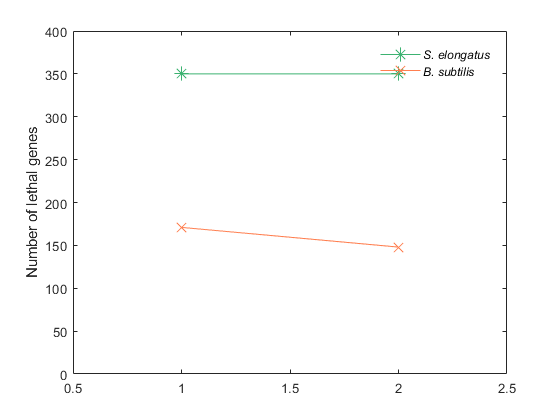

%KO analysis
% [A_SingleDelBs D_SingleDelBs C_SingleDelDBs C_SingleDelABs] = singleGeneDeletionComparison(SingleM{2,1},SingleM{3,1},modelCo2{1,1});
% [A_SingleDelEc D_SingleDelEc C_SingleDelDEc C_SingleDelAEc] = singleGeneDeletionComparison(SingleM{2,1},SingleM{4,1},modelCo2{2,1});
% [A_SingleDelEcW D_SingleDelEcW C_SingleDelDEcW C_SingleDelAEcW] = singleGeneDeletionComparison(SingleM{2,1},SingleM{5,1},modelCo2{3,1});
% [A_SingleDelYl D_SingleDelYl C_SingleDelDYl C_SingleDelAYl] = singleGeneDeletionComparison(SingleM{2,1},SingleM{6,1},modelCo2{4,1});

figure
%subplot(4,1,1)
A=numel(D_SingleDelBs.Effect)-numel(setdiff(D_SingleDelBs.Effect,C_SingleDelDBs.Effect));
B=numel(A_SingleDelBs.Effect)-numel(setdiff(A_SingleDelBs.Effect,C_SingleDelABs.Effect));
C=numel(D_SingleDelBs.Effect);
D=numel(A_SingleDelBs.Effect);
A1=[C D;A B];
plot([1 2],[D B],'-*','MarkerSize',10,'MarkerEdgeColor',[0.2344    0.6992    0.4414],'MarkerFaceColor',[0.5938    0.9833    0.5938],'Color',[0.2344    0.6992    0.4414])
hold on
plot([1 2],[C A],'-x','MarkerSize',10,'MarkerEdgeColor',[1.0000    0.4961    0.3125],'MarkerFaceColor',[1.0000    0.4961    0.3125],'Color',[1.0000    0.4961    0.3125])
%hDataSeries =bar(A1,0.65)
%hDataSeries =bar(A1,0.65)
set(gca, 'xlim',[0.5,2.5],'ylim',[0,400]);
ylabel('Number of lethal genes');
legend('\itS. elongatus','\itB. subtilis');
legend boxoff

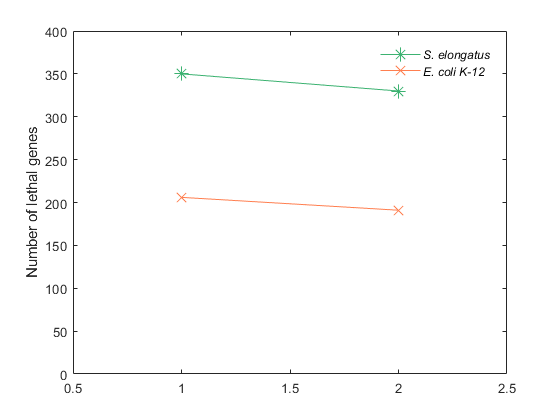


%subplot(4,1,2)
figure
A=numel(D_SingleDelEc.Effect)-numel(setdiff(D_SingleDelEc.Effect,C_SingleDelDEc.Effect));
B=numel(A_SingleDelEc.Effect)-numel(setdiff(A_SingleDelEc.Effect,C_SingleDelAEc.Effect));
C=numel(D_SingleDelEc.Effect);
D=numel(A_SingleDelEc.Effect);
plot([1 2],[D B],'-*','MarkerSize',10,'MarkerEdgeColor',[0.2344    0.6992    0.4414],'MarkerFaceColor',[0.5938    0.9833    0.5938],'Color',[0.2344    0.6992    0.4414])
hold on
plot([1 2],[C A],'-x','MarkerSize',10,'MarkerEdgeColor',[1.0000    0.4961    0.3125],'MarkerFaceColor',[1.0000    0.4961    0.3125],'Color',[1.0000    0.4961    0.3125])
% A1=[C D;A B];
% hDataSeries =bar(A1)
% hDataSeries =bar(A1,0.65)
set(gca, 'xlim',[0.5,2.5],'ylim',[0,400]);
ylabel('Number of lethal genes');
legend('\itS. elongatus','\itE. coli K-12');
legend boxoff

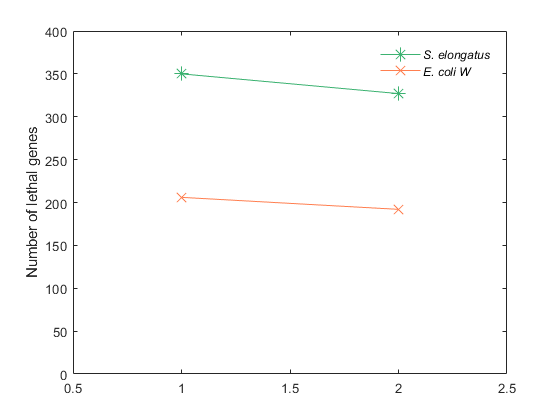


figure
%subplot(4,1,3)
A=numel(D_SingleDelEcW.Effect)-numel(setdiff(D_SingleDelEcW.Effect,C_SingleDelDEcW.Effect));
B=numel(A_SingleDelEcW.Effect)-numel(setdiff(A_SingleDelEcW.Effect,C_SingleDelAEcW.Effect));
C=numel(D_SingleDelEcW.Effect);
D=numel(A_SingleDelEcW.Effect);
plot([1 2],[D B],'-*','MarkerSize',10,'MarkerEdgeColor',[0.2344    0.6992    0.4414],'MarkerFaceColor',[0.5938    0.9833    0.5938],'Color',[0.2344    0.6992    0.4414])
hold on
plot([1 2],[C A],'-x','MarkerSize',10,'MarkerEdgeColor',[1.0000    0.4961    0.3125],'MarkerFaceColor',[1.0000    0.4961    0.3125],'Color',[1.0000    0.4961    0.3125])
% A1=[C D;A B];
% hDataSeries =bar(A1,0.65)
% % hDataSeries =bar(A1,0.65)
set(gca, 'xlim',[0.5,2.5],'ylim',[0,400]);
ylabel('Number of lethal genes');
legend('\itS. elongatus','\itE. coli W');
legend boxoff

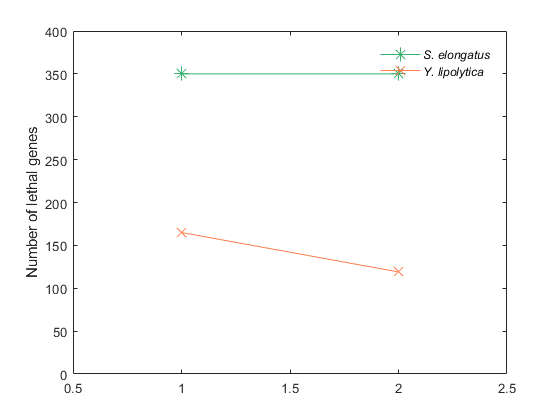


figure
%subplot(4,1,4)
A=numel(D_SingleDelYl.Effect)-numel(setdiff(D_SingleDelYl.Effect,C_SingleDelDYl.Effect));
B=numel(A_SingleDelYl.Effect)-numel(setdiff(A_SingleDelYl.Effect,C_SingleDelAYl.Effect));
C=numel(D_SingleDelYl.Effect);
D=numel(A_SingleDelYl.Effect);
plot([1 2],[D B],'-*','MarkerSize',10,'MarkerEdgeColor',[0.2344    0.6992    0.4414],'MarkerFaceColor',[0.5938    0.9833    0.5938],'Color',[0.2344    0.6992    0.4414])
hold on
plot([1 2],[C A],'-x','MarkerSize',10,'MarkerEdgeColor',[1.0000    0.4961    0.3125],'MarkerFaceColor',[1.0000    0.4961    0.3125],'Color',[1.0000    0.4961    0.3125])
% A1=[C D;A B];
% hDataSeries =bar(A1,0.7)
% hDataSeries =bar(A1,0.65)
set(gca, 'xlim',[0.5,2.5],'ylim',[0,400]);
ylabel('Number of lethal genes');
c = categorical({'Monoculture','Coculture'});
legend('\itS. elongatus','\itY. lipolytica');
legend boxoff




% modelCo=modelCo2{2,1};
% [C_grRatio,C_grRatio_coY,C_grRatio_coA,C_grRateKO,C_grRateYeast,C_grRateAlgae,C_grRateWT,C_hasEffect,C_delRxns,C_fluxSolution,C_modelos] = singleGeneDeletionCM(modelCo);


Clustergram object with 22 rows of nodes and 20 columns of nodes.



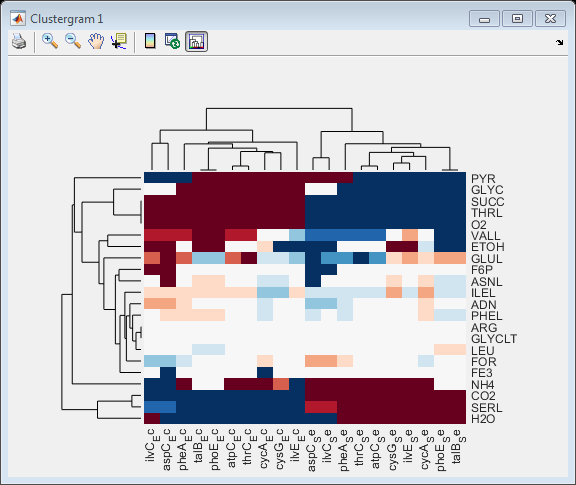

ExpKO_genes={'b0928','b2599','b3368','b3770','b3774','b4208','b0008','b3731','b0241','b0004'};
% sharedP={};cont=1;unD={};unA={};SPM_D=SPM_D1;cont2=1;
% for i=1:numel(ExpKO_genes)
%     geneInd=strmatch(ExpKO_genes{i},modelCo.genes,'exact');
%     [SPM_rxns,SPM_D1, Un_D, Un_A] = sharedPoolCM(C_modelos{geneInd,1},1);
%     for j=1:numel(SPM_D1.Name)
%     sharedP{j,cont}=table2array(SPM_D1.Name(j));
%     sharedP{j,cont+1}=table2array(SPM_D1.Full_Name(j));
%     sharedP{j,cont+2}=SPM_D1.Rxn(j);
%     sharedP{j,cont+3}=SPM_D1.Flux(j);
%     end
% 
%     for j=1:numel(Un_D.Name)
%     unD{j,cont2}=table2array(Un_D.Name(j));
%     unD{j,cont2+1}=Un_D.Flux(j);
%     end
%     
%     for j=1:numel(Un_A.Name)
%     unA{j,cont2}=table2array(Un_A.Name(j));
%      unA{j,cont2+1}=Un_A.Flux(j);
%     end
%     cont=cont+4;
%     cont2=cont2+2;
% end

sharedP={'ADNtex_A','ADNtex_D',0.0347543370942276,-0.0347543370942276,'ADNtex_A','ADNtex_D',0.0231975105782567,-0.0231975105782567,'ASNLtex_A','ASNtex_D',-0.0202068705335705,0.0202068705335705,'ADNtex_A','ADNtex_D',0.000396745350258243,-0.000396745350258243,'ADNtex_A','ADNtex_D',0.0347543370944550,-0.0347543370944550,'ADNtex_A','ADNtex_D',-0.0184121115278231,0.0184121115278231,'ADNtex_A','ADNtex_D',0.000396745350258243,-0.000396745350258243,'ADNtex_A','ADNtex_D',-0.00593775197580726,0.00593775197580726,'ADNtex_A','ADNtex_D',0.000396745350258243,-0.000396745350258243,'ADNtex_A','ADNtex_D',-0.00157327839792742,0.00157327839792742;'ASNLtex_A','ASNtex_D',0.126943025387845,-0.126943025387845,'ASNLtex_A','ASNtex_D',-0.00651654674504698,0.00651654674504698,'CO2tex_A','CO2tex_D',-367.874859727019,369.864859727019,'ASNLtex_A','ASNtex_D',-0.00651654674504698,0.00651654674504698,'ASNLtex_A','ASNtex_D',-0.00651654674504698,0.00651654674504698,'ASNLtex_A','ASNtex_D',-0.0202068705335705,0.0202068705335705,'ASNLtex_A','ASNtex_D',0.0186996121298080,-0.0186996121298080,'ASNLtex_A','ASNtex_D',-0.00651654674504698,0.00651654674504698,'ASNLtex_A','ASNtex_D',0.0186996121298080,-0.0186996121298080,'ASNLtex_A','ASNtex_D',-0.00651654674504698,0.00651654674504698;'CO2tex_A','CO2tex_D',-462.075553138480,464.065553138480,'CO2tex_A','CO2tex_D',-194.864202404618,196.854202404619,'ETOHtex_A','ETOHtex_D',-0.568206509810352,0.568206509810352,'CO2tex_A','CO2tex_D',-340.537043388192,342.527043388192,'CO2tex_A','CO2tex_D',-464.095082250005,466.085082250005,'CO2tex_A','CO2tex_D',-462.623199394712,464.613199394712,'CO2tex_A','CO2tex_D',-461.092404232799,463.082404232799,'CO2tex_A','CO2tex_D',-464.448220404136,466.438220404136,'CO2tex_A','CO2tex_D',-461.092404232799,463.082404232799,'CO2tex_A','CO2tex_D',-460.545615465110,462.535615465110;'COBALT2tex_A','COBALT2tex_D',1.93935125025746e-06,1.78319282895245e-07,'COBALT2tex_A','COBALT2tex_D',1.93935125025746e-06,1.78319282895245e-07,'FORtex_A','FORtex_D',-0.00327985187129798,0.00327985187129798,'COBALT2tex_A','COBALT2tex_D',1.93935125025746e-06,1.78319282895245e-07,'COBALT2tex_A','COBALT2tex_D',1.93935125025746e-06,1.78319282895245e-07,'ETOHtex_A','ETOHtex_D',0.0157919092686143,-0.0157919092686143,'COBALT2tex_A','COBALT2tex_D',1.93935125025746e-06,1.78319282895245e-07,'COBALT2tex_A','COBALT2tex_D',1.93935125025746e-06,1.78319282895245e-07,'COBALT2tex_A','COBALT2tex_D',1.93935125025746e-06,1.78319282895245e-07,'COBALT2tex_A','COBALT2tex_D',1.93935125025746e-06,1.78319282895245e-07;'ETOHtex_A','ETOHtex_D',4.11231724102527,-4.11231724102527,'ETOHtex_A','ETOHtex_D',0.00509275866204462,-0.00509275866204462,'GLULtex_A','GLUtex_D',-0.0199999999999818,0.0199999999999818,'ETOHtex_A','ETOHtex_D',-0.182258143066179,0.182258143066179,'ETOHtex_A','ETOHtex_D',2.20949928571429,-2.20949928571429,'FE3tex_A','FE3tex_D',-98.8584386670636,0.000173109563093021,'ETOHtex_A','ETOHtex_D',1.99101969086018,-1.99101969086018,'ETOHtex_A','ETOHtex_D',0.00509275866204462,-0.00509275866204462,'ETOHtex_A','ETOHtex_D',1.99101969086018,-1.99101969086018,'ETOHtex_A','ETOHtex_D',0.00509275866204462,-0.00509275866204462;'F6Ptex_A','F6Ptex_D',16.1573062943737,-16.1573062943737,'FORtex_A','FORtex_D',-0.0243069772652689,0.0243069772652689,'GLYCtex_A','GLYCtex_D',370.067622420447,-370.067622420447,'FORtex_A','FORtex_D',-0.00150621203738410,0.00150621203738410,'F6Ptex_A','F6Ptex_D',16.1220269218418,-16.1220269218418,'FORtex_A','FORtex_D',0.0151322596565251,-0.0151322596565251,'FE3tex_A','FE3tex_D',0.000605698166395996,5.58263863013053e-05,'FE3tex_A','FE3tex_D',0.000605698166395996,5.58263863013053e-05,'FE3tex_A','FE3tex_D',0.000605698166395996,5.58263863013053e-05,'FORtex_A','FORtex_D',0.000462744231299439,-0.000462744231299439;'FE3tex_A','FE3tex_D',-99.0202904857358,5.58263863013053e-05,'GLULtex_A','GLUtex_D',0.0634069957690144,-0.0634069957690144,'H2Otex_A','H2Otex_D',-108.623985914128,108.395537222125,'GLULtex_A','GLUtex_D',-0.0400629657525542,0.0400629657525542,'FE3tex_A','FE3tex_D',0.000605698166395996,5.58263863013053e-05,'GLULtex_A','GLUtex_D',-0.0199999999998681,0.0199999999998681,'FORtex_A','FORtex_D',-0.00150727951688623,0.00150727951688623,'FORtex_A','FORtex_D',0.00482721780986140,-0.00482721780986140,'FORtex_A','FORtex_D',-0.00150727951688623,0.00150727951688623,'GLULtex_A','GLUtex_D',0.211132825175241,-0.211132825175241;'FORtex_A','FORtex_D',-0.0358638037806713,0.0358638037806713,'GLYCLTtex_A','GLYCLTtex_D',-5.18970381335748e-05,5.18970381335748e-05,'Htex_A','Htex_D',-0.851588487036679,1.98999981997224,'GLYCLTtex_A','GLYCLTtex_D',-5.18970381335748e-05,5.18970381335748e-05,'FORtex_A','FORtex_D',-0.0358648712610830,0.0358648712610830,'GLYCtex_A','GLYCtex_D',57.2508761624267,-57.2508761624266,'GLULtex_A','GLUtex_D',-0.0400629657526679,0.0400629657526679,'GLULtex_A','GLUtex_D',0.0634069957684460,-0.0634069957684460,'GLULtex_A','GLUtex_D',-0.0400629657526679,0.0400629657526679,'GLYCLTtex_A','GLYCLTtex_D',-5.18970381335748e-05,5.18970381335748e-05;'GLULtex_A','GLUtex_D',1.19849272717636,-1.19849272717636,'GLYCtex_A','GLYCtex_D',197.306760566716,-197.306760566716,'ILELtex_A','ILEtex_D',-0.0312935816217532,0.0312935816217532,'GLYCtex_A','GLYCtex_D',387.377465053572,-387.377465053573,'GLULtex_A','GLUtex_D',0.0634069957687871,-0.0634069957687871,'H2Otex_A','H2Otex_D',-51.7982958316990,2.13905280616473,'GLYCLTtex_A','GLYCLTtex_D',-5.18970381335748e-05,5.18970381335748e-05,'GLYCLTtex_A','GLYCLTtex_D',-5.18970381335748e-05,5.18970381335748e-05,'GLYCLTtex_A','GLYCLTtex_D',-5.18970381335748e-05,5.18970381335748e-05,'GLYCtex_A','GLYCtex_D',270.071506236500,-270.071506236500;'GLYCLTtex_A','GLYCLTtex_D',-5.18970381335748e-05,5.18970381335748e-05,'H2Otex_A','H2Otex_D',-293.563949747537,292.851080201895,'NH4tex_A','NH4tex_D',0.0604137410671228,0.810477830615355,'H2Otex_A','H2Otex_D',-117.557005541109,116.841358217688,'GLYCLTtex_A','GLYCLTtex_D',-5.18970381335748e-05,5.18970381335748e-05,'Htex_A','Htex_D',505.811254306585,-405.811254306585,'GLYCtex_A','GLYCtex_D',266.885188942715,-266.885188942715,'GLYCtex_A','GLYCtex_D',59.0732108382956,-59.0732108382956,'GLYCtex_A','GLYCtex_D',266.885188942715,-266.885188942715,'H2Otex_A','H2Otex_D',-3.44177293779421,2.72640339215036;'H2Otex_A','H2Otex_D',-34.4645080213395,-15.7609092826182,'Htex_A','Htex_D',-1.01509545859153,1.98999994194253,'O2tex_A','O2tex_D',238.660502787100,-243.122108885084,'Htex_A','Htex_D',-46.9655550813538,47.9460151202584,'H2Otex_A','H2Otex_D',15.2533730990650,-15.9683694910406,'ILELtex_A','ILEtex_D',-0.0312935816217532,0.0312935816217532,'H2Otex_A','H2Otex_D',-0.805608102239830,0.0905414056817335,'H2Otex_A','H2Otex_D',-3.15442722895807,2.43945801335406,'H2Otex_A','H2Otex_D',-0.805608102239830,0.0905414056817335,'Htex_A','Htex_D',192.142218787550,-191.162314304194;'Htex_A','Htex_D',529.912697874068,-429.912697874068,'ILELtex_A','ILEtex_D',0.0225375105783314,-0.0225375105783314,'PYRtex_A','PYRtex_D',258.449715564354,-258.449715564354,'ILELtex_A','ILEtex_D',0.0225375105783314,-0.0225375105783314,'Htex_A','Htex_D',431.874568308552,-430.895410132536,'NH4tex_A','NH4tex_D',0.372848423278356,0.498043148404236,'Htex_A','Htex_D',194.034055371142,-193.054756585955,'Htex_A','Htex_D',406.732513522539,-405.753409699256,'Htex_A','Htex_D',194.034055371142,-193.054756585955,'ILELtex_A','ILEtex_D',0.0225375105783314,-0.0225375105783314;'ILELtex_A','ILEtex_D',0.0225375105783314,-0.0225375105783314,'Ktex_A','Ktex_D',0.0151419111424502,5.39105258212658e-08,'SERLtex_A','SERtex_D',-1.54117420639136,1.54117420639136,'Ktex_A','Ktex_D',0.0151419111424502,5.39105258212658e-08,'ILELtex_A','ILEtex_D',0.0225375105783314,-0.0225375105783314,'O2tex_A','O2tex_D',257.669967263592,-237.416176194811,'ILELtex_A','ILEtex_D',0.0225375105783314,-0.0225375105783314,'ILELtex_A','ILEtex_D',0.0225375105783314,-0.0225375105783314,'ILELtex_A','ILEtex_D',0.0225375105783314,-0.0225375105783314,'Ktex_A','Ktex_D',0.0151419111424502,5.39105258212658e-08;'Ktex_A','Ktex_D',0.0151419111424502,5.39105258212658e-08,'MG2tex_A','MG2tex_D',0.000672954865990505,0.000390694934480962,'SUCCtex_A','SUCCtex_D',370.361194770774,-370.361194770774,'MG2tex_A','MG2tex_D',0.000672954865990505,0.000390694934480962,'Ktex_A','Ktex_D',0.0151419111424502,5.39105258212658e-08,'PHELtex_A','PHEtex_D',-0.0200080057607011,0.0200080057607011,'Ktex_A','Ktex_D',0.0151419111424502,5.39105258212658e-08,'Ktex_A','Ktex_D',0.0151419111424502,5.39105258212658e-08,'Ktex_A','Ktex_D',0.0151419111424502,5.39105258212658e-08,'MG2tex_A','MG2tex_D',0.000672954865990505,0.000390694934480962;'MG2tex_A','MG2tex_D',0.000672954865990505,0.000390694934480962,'NH4tex_A','NH4tex_D',0.367827148642732,0.750891738370115,'THRLtex_A','THRtex_D',1.57246778801311,-1.57246778801311,'NH4tex_A','NH4tex_D',-0.788972836088306,1.90769172310138,'MG2tex_A','MG2tex_D',0.000672954865990505,0.000390694934480962,'PYRtex_A','PYRtex_D',52.1736357606087,-52.1736357606087,'LEUtex_A','LEUtex_D',-0.0183382537434227,0.0183382537434227,'MG2tex_A','MG2tex_D',0.000672954865990505,0.000390694934480962,'LEUtex_A','LEUtex_D',-0.0183382537434227,0.0183382537434227,'NH4tex_A','NH4tex_D',0.413422108132750,0.705296778880324;'NH4tex_A','NH4tex_D',-1.15067361906949,2.26939250607950,'O2tex_A','O2tex_D',244.137821112075,-248.476082811899,[],[],[],[],'O2tex_A','O2tex_D',229.261826096881,-233.598698907815,'NH4tex_A','NH4tex_D',-0.996389876421404,2.11510876343425,'SERLtex_A','SERtex_D',-1.52276209486342,1.52276209486342,'MG2tex_A','MG2tex_D',0.000672954865990505,0.000390694934480962,'NH4tex_A','NH4tex_D',0.417786581710288,0.700932305301535,'MG2tex_A','MG2tex_D',0.000672954865990505,0.000390694934480962,'O2tex_A','O2tex_D',231.795013596440,-236.132025296262;'O2tex_A','O2tex_D',258.349154657309,-237.931142477973,'PHELtex_A','PHEtex_D',0.0143717559943752,-0.0143717559943752,[],[],[],[],'PHELtex_A','PHEtex_D',-0.00645241451900347,0.00645241451900347,'O2tex_A','O2tex_D',233.458045925890,-237.795244202546,'SUCCtex_A','SUCCtex_D',465.910715193653,-465.910715193653,'O2tex_A','O2tex_D',231.810944546028,-236.148107670394,'O2tex_A','O2tex_D',233.593914264379,-237.931126129221,'O2tex_A','O2tex_D',231.810944546028,-236.148107670394,'PHELtex_A','PHEtex_D',-0.00645241451900347,0.00645241451900347;'PHELtex_A','PHEtex_D',0.0143717559943752,-0.0143717559943752,'PItex_A','PItex_D',0.0748303314514942,0.0148698637963207,[],[],[],[],'PItex_A','PItex_D',0.0748303314524037,0.0148698637962070,'PHELtex_A','PHEtex_D',-0.00645241451900347,0.00645241451900347,'THRLtex_A','THRtex_D',1.35368955767399,-1.35368955767399,'PHELtex_A','PHEtex_D',0.0143717559943752,-0.0143717559943752,'PHELtex_A','PHEtex_D',-0.00645241451900347,0.00645241451900347,'PHELtex_A','PHEtex_D',0.0143717559943752,-0.0143717559943752,'PItex_A','PItex_D',0.0748303314529721,0.0148698637962070;'PItex_A','PItex_D',-16.0824759629217,16.1721761581687,'PYRtex_A','PYRtex_D',-97.7599383678898,97.7599383678898,[],[],[],[],'PYRtex_A','PYRtex_D',269.152260691865,-269.152260691865,'PItex_A','PItex_D',-16.0471965903886,16.1368967856380,[],[],[],[],'PItex_A','PItex_D',0.0748303314521763,0.0148698637963207,'PItex_A','PItex_D',0.0748303314529721,0.0148698637952975,'PItex_A','PItex_D',0.0748303314521763,0.0148698637963207,'PYRtex_A','PYRtex_D',265.031688747286,-265.031688747286;'PYRtex_A','PYRtex_D',-3.65686592374846,3.65686592374846,'SERLtex_A','SERtex_D',-1.42858740481972,1.42858740481972,[],[],[],[],'SERLtex_A','SERtex_D',-1.40578663959161,1.40578663959161,'PYRtex_A','PYRtex_D',-1.51985011650129,1.51985011650129,[],[],[],[],'PYRtex_A','PYRtex_D',267.817623829889,-267.817623829889,'PYRtex_A','PYRtex_D',54.8028939592548,-54.8028939592547,'PYRtex_A','PYRtex_D',267.817623829889,-267.817623829889,'SERLtex_A','SERtex_D',-1.40381661584320,1.40381661584320;'SERLtex_A','SERtex_D',-0.0666598622740366,0.0666598622740366,'SO4tex_A','SO4tex_D',0.0195649506346172,0.00542703366568276,[],[],[],[],'SO4tex_A','SO4tex_D',0.0195649506347309,0.00542703366568276,'SERLtex_A','SERtex_D',-0.0666598622747188,0.0666598622747188,[],[],[],[],'SERLtex_A','SERtex_D',-2.15909377160870,2.15909377160870,'SERLtex_A','SERtex_D',-1.39945214226589,1.39945214226589,'SERLtex_A','SERtex_D',-2.15909377160870,2.15909377160870,'SO4tex_A','SO4tex_D',0.0195649506346172,0.00542703366568276;'SO4tex_A','SO4tex_D',0.0195649506347309,0.00542703366568276,'SUCCtex_A','SUCCtex_D',197.657157622605,-197.657157622605,[],[],[],[],'SUCCtex_A','SUCCtex_D',341.474868588193,-341.474868588193,'SO4tex_A','SO4tex_D',0.0195649506347309,0.00542703366568276,[],[],[],[],'SO4tex_A','SO4tex_D',0.0195649506346172,0.00542703366568276,'SO4tex_A','SO4tex_D',0.0195649506347309,0.00542703366568276,'SO4tex_A','SO4tex_D',0.0195649506346172,0.00542703366568276,'SUCCtex_A','SUCCtex_D',463.563656593443,-463.563656593443;'SUCCtex_A','SUCCtex_D',467.161793472314,-467.161793472313,'THRLtex_A','THRtex_D',1.62753258803059,-1.62753258803059,[],[],[],[],'THRLtex_A','THRtex_D',3.09682405159481,-3.09682405159481,'SUCCtex_A','SUCCtex_D',466.890326950510,-466.890326950510,[],[],[],[],'SUCCtex_A','SUCCtex_D',463.596141489800,-463.596141489800,'SUCCtex_A','SUCCtex_D',467.162080926500,-467.162080926500,'SUCCtex_A','SUCCtex_D',463.596141489800,-463.596141489800,'THRLtex_A','THRtex_D',1.55411912555292,-1.55411912555292;'THRLtex_A','THRtex_D',0.324316804942896,-0.324316804942896,'VALLtex_A','VALtex_D',0.0678205853314466,-0.0678205853314466,[],[],[],[],'VALLtex_A','VALtex_D',-0.0291737005549066,0.0291737005549066,'THRLtex_A','THRtex_D',1.59286210848211,-1.59286210848211,[],[],[],[],'THRLtex_A','THRtex_D',1.77418868636073,-1.77418868636073,'THRLtex_A','THRtex_D',1.71493837569381,-1.71493837569381,'THRLtex_A','THRtex_D',1.77418868636073,-1.77418868636073,'VALLtex_A','VALtex_D',0.0678205853314466,-0.0678205853314466;'VALLtex_A','VALtex_D',0.0678205853314466,-0.0678205853314466,[],[],[],[],[],[],[],[],[],[],[],[],'VALLtex_A','VALtex_D',0.0678205853314466,-0.0678205853314466,[],[],[],[],'VALLtex_A','VALtex_D',0.0861588390748693,-0.0861588390748693,'VALLtex_A','VALtex_D',0.0678205853314466,-0.0678205853314466,'VALLtex_A','VALtex_D',0.0861588390748693,-0.0861588390748693,[],[],[],[]};
%Creating the vector of unique shared metabolites by KO
C = vertcat(sharedP(:,1),sharedP(:,5),sharedP(:,9),sharedP(:,13),sharedP(:,17),sharedP(:,21),sharedP(:,25),sharedP(:,29), sharedP(:,33), sharedP(:,37));
C=C(~cellfun('isempty',C)) ;
C=unique(C);
Val=numel(C);
%Looking fot the specific KO data
 C={'ADNtex_A';'ARGtex_A';'ASNLtex_A';'CO2tex_A';'ETOHtex_A';'F6Ptex_A';'FE3tex_A';'FORtex_A';'GLULtex_A';'GLYCLTtex_A';'GLYCtex_A';'H2Otex_A';'ILELtex_A';'LEUtex_A';'NH4tex_A';'O2tex_A';'PHELtex_A';'PYRtex_A';'SERLtex_A';'SUCCtex_A';'THRLtex_A';'VALLtex_A'};
Val=numel(C);
 cont=1;Metabolites={};
for i=1:Val 
%      Ind2=strmatch(C{i,1},modelCo.mets,'exact');   
%      Metabolites{end+1,1}=modelCo.metNames{Ind2,1};
    for j=[1:2:2*numel(ExpKO_genes)]   
        if cont<39
    A=sharedP(:,cont);A=A(~cellfun('isempty',A));A=unique(A);
     Ind=strmatch(C{i,1},A,'exact');   
    
    aux=j+1;
    if ~isempty(Ind)
    C{i,aux}=cell2mat(sharedP(Ind,cont+2));
    C{i,aux+1}=cell2mat(sharedP(Ind,cont+3));
    %j=j+1;   
    else
    C{i,aux}=0;
    C{i,aux+1}=0;
    %j=j+1;        
    end
 cont=cont+4;  
        else
            break
        end
    end
cont=1;

end
SPMss={};
for i=1:numel(C)/21
    String=C{i,1};
    %SPMss{i,1}=upper(String{1,1}(1:end-5));
    SPMss{i,1}=strrep(String(1:end-5), 'TEX_', ' ');
    SPMss{i,1}=strrep(SPMss{i,1}, 'T_', '');
    SPMss{i,1}=strrep(SPMss{i,1}, ' A', '');
end
genes={'b0928';'b2599';'b3368';'b3770';'b3774';'b4208';'b0008';'b3731';'b0241';'b0004'};
Genes_all={'aspC_Ec';'aspC_Se';
'pheA_Ec';'pheA_Se';
'cysG_Ec';'cysG_Se';
'ilvE_Ec';'ilvE_Se';
'ilvC_Ec';'ilvC_Se';
'cycA_Ec';'cycA_Se';
'talB_Ec';'talB_Se';'atpC_Ec';'atpC_Se';'phoE_Ec';'phoE_Se';'thrC_Ec';'thrC_Se';};
%Convertions to improve the plot
aux=cell2mat(C(:,2:21));

aux(aux>0.1)=0.1;
aux(aux<-0.1)=-0.1;
cg=clustergram(aux(:,1:end),'RowLabels',SPMss(1:end),...
                                 'ColumnLabels',Genes_all(1:end),'Colormap',redbluecmap)

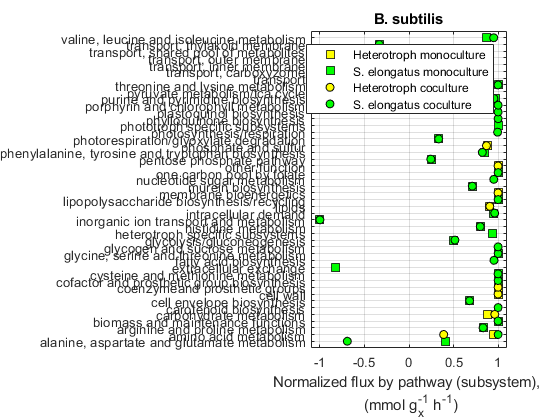

% All_subsBs = predictedExpressionCM(modelCo2{1,1},SingleM{3,1},SingleM{2,1})
% All_subsK12 = predictedExpressionCM(modelCo2{2,1},SingleM{4,1},SingleM{2,1})
% All_subsW = predictedExpressionCM(modelCo2{3,1},SingleM{5,1},SingleM{2,1})
% All_subsYl = predictedExpressionCM(modelCo2{4,1},SingleM{6,1},SingleM{2,1})

All_subsBs={'alanine, aspartate and glutamate metabolism',-0.692776219374356,1000,0.411406578887023,1000;'amino acid metabolism',1,0.388677899541878,1000,0.947218308301251;'arginine and proline metabolism',0.831658058934055,1000,0.831658058933776,1000;'biomass and maintenance functions',1,1,1,1;'carbohydrate metabolism',1000,0.962774798234599,1000,0.880662713172172;'carotenoid biosynthesis',1,1000,1000,1000;'cell envelope biosynthesis',0.680266026234230,1000,0.680266026232688,1000;'cell wall',1000,1,1000,1;'coenzymeand prosthetic groups',1000,1,1000,1;'cofactor and prosthetic group biosynthesis',0.999990345215227,1000,0.999990345931222,1000;'cysteine and methionine metabolism',1,1000,1,1000;'extracellular exchange',1000,1000,-0.827582155765451,1000;'fatty acid biosynthesis',0.953948729559921,1000,1000,1000;'glycine, serine and threonine metabolism',1,1000,1,1000;'glycogen and sucrose metabolism',1,1000,1000,1000;'glycolysis/gluconeogenesis',0.515695035950709,1000,0.504575144666887,1000;'heterotroph specific subsystems',1000,1000,0.941670636442319,1000;'histidine metabolism',0.799999999997083,1000,0.799999999999673,1000;'inorganic ion transport and metabolism',-1,1000,-1,1000;'intracellular demand',0.961736627931208,1000,0.951434898318820,1000;'lipids',1000,0.906345923777537,1000,0.906345908691321;'lipopolysaccharide biosynthesis/recycling',1,1000,1,1000;'membrane bioenergetics',1000,1,1000,1;'murein biosynthesis',0.710650822524089,1000,0.710650822522947,1000;'nucleotide sugar metabolism',0.950951072769982,1000,1000,1000;'one carbon pool by folate',1,1000,1,1000;'other function',1000,1,1000,1;'pentose phosphate pathway',0.245239154714885,1000,0.249520185419611,1000;'phenylalanine, tyrosine and tryptophan biosynthesis',0.822857875029919,1000,0.842327439960087,1000;'phosphate and sulfur',1000,0.869878573120592,1000,0.884450768669755;'photorespiration/glyoxylate degradation',0.333185326902856,1000,0.333315173799879,1000;'photosynthesis/respiration',0.994841690263629,1000,1000,1000;'phototroph specific subsystems',1000,1000,0.999795796700943,1000;'phylloquinone biosynthesis',1,1000,1000,1000;'plastoquinol biosynthesis',1,1000,1000,1000;'porphyrin and chlorophyll metabolism',1,1000,1000,1000;'purine and pyrimidine biosynthesis',0.953086552731658,0.870003195732992,0.967051359651934,0.914523159988200;'pyruvate metabolism/tca cycle',-0.186629837678153,1000,0.468348653332384,1000;'threonine and lysine metabolism',1,1000,1,1000;'transport',-0.0341908807679330,-0.953658138059554,1000,1000;'transport, carboxyzome',0.596806387225548,1000,0.596806387225545,1000;'transport, inner membrane',0.340558744165743,1000,0.272596039561267,1000;'transport, outer membrane',0.251312366402055,1000,0.243117852483940,0.284305300178118;'transport, shared pool of metabolites',1000,1000,-1,-0.920827138681692;'transport, thylakoid membrane',-0.333333278401013,1000,-0.333333263538200,1000;'valine, leucine and isoleucine metabolism',0.950950117018355,1000,0.866630258851974,1000};
All_subsK12 ={'alanine, aspartate and glutamate metabolism',-0.897543001164628,-0.740500663129490,0.411406578887023,-0.704205450938573;'amino acid metabolism',1,1000,1000,1000;'arginine and proline metabolism',0.831658058934422,0.636010577882183,0.831658058933776,0.636010577882683;'biomass and maintenance functions',1,1,1,1;'carotenoid biosynthesis',1,1000,1000,1000;'cell envelope biosynthesis',0.680266026233763,0.581434882561075,0.680266026232688,0.581434882560845;'cofactor and prosthetic group biosynthesis',0.999973547401018,1,0.999990345931222,1;'cysteine and methionine metabolism',1,1,1,1;'extracellular exchange',1000,1000,-0.827582155765451,-1;'fatty acid biosynthesis',0.953948729559912,1000,1000,1000;'glycine, serine and threonine metabolism',1,-0.189927073473409,1,1;'glycogen and sucrose metabolism',1,1000,1000,1000;'glycolysis/gluconeogenesis',0.471511117337528,0.290759043029233,0.504575144666887,0.376147001141922;'heterotroph specific subsystems',0.604199602387738,0.999983184904522,0.941670636442319,0.968749424538882;'histidine metabolism',0.800000000003053,1,0.799999999999673,1;'inorganic ion transport and metabolism',-1,0.976426632496052,-1,0.999728142399236;'intracellular demand',0.970195585271981,1,0.951434898318820,1;'lipopolysaccharide biosynthesis/recycling',1,1,1,1;'murein biosynthesis',0.710650822524707,1,0.710650822522947,1;'one carbon pool by folate',1,1,1,1;'oxidative phosphorylation',1000,0.968941498382695,1000,1000;'pentose phosphate pathway',0.242184925430474,-1,0.249520185419611,0.738472282652723;'phenylalanine, tyrosine and tryptophan biosynthesis',0.820987442825997,0.816626559624342,0.842327439960087,0.808885201793006;'photorespiration/glyoxylate degradation',0.905636431021101,1000,0.333315173799879,1000;'photosynthesis/respiration',0.992216442571092,1000,1000,1000;'phototroph specific subsystems',1000,1000,0.999795796700943,1000;'phylloquinone biosynthesis',1,1000,1000,1000;'plastoquinol biosynthesis',1,1000,1000,1000;'porphyrin and chlorophyll metabolism',1,1000,1000,1000;'purine and pyrimidine biosynthesis',0.931156904994400,0.787969720323316,0.967051359651934,0.746814253983103;'pyruvate metabolism/tca cycle',0.283649185336164,0.411192784103287,0.468348653332384,0.774781864776140;'threonine and lysine metabolism',1,0.443486337656664,1,0.341455218904494;'transport',0.0383332444398673,1000,1000,1000;'transport, carboxyzome',0.596806387225546,1000,0.596806387225545,1000;'transport, inner membrane',0.362283921668028,-0.491363480893050,0.272596039561267,-0.748699849661503;'transport, outer membrane',0.280580710481910,-0.266211732131439,0.243117852483940,0.0418821009425536;'transport, shared pool of metabolites',1000,1000,-1,1000;'transport, thylakoid membrane',-0.333333290173539,1000,-0.333333263538200,1000;'valine, leucine and isoleucine metabolism',0.989197460075979,0.325602274481176,0.866630258851974,0.308777805548743};
All_subsW ={'alanine, aspartate and glutamate metabolism',-0.234537226265374,-0.745090622957288,0.411406578887023,-0.704205451015691;'alternate carbon metabolism',1000,0.999959972221134,1000,1000;'amino acid metabolism',1,1000,1000,1000;'arginine and proline metabolism',0.831658058934150,0.636010577882524,0.831658058933776,0.636010577884193;'biomass and maintenance functions',1,1,1,1;'carotenoid biosynthesis',1,1000,1000,1000;'cell envelope biosynthesis',0.680266026232536,0.581434882560752,0.680266026232688,0.581434882560423;'cofactor and prosthetic group biosynthesis',0.999976408163819,1,0.999990345931222,1;'cysteine and methionine metabolism',1,1,1,1;'extracellular exchange',1000,1,-0.827582155765451,1;'fatty acid biosynthesis',0.953948729559735,1000,1000,1000;'glycine, serine and threonine metabolism',1,-1,1,1;'glycogen and sucrose metabolism',1,1000,1000,1000;'glycolysis/gluconeogenesis',0.387557566161256,0.294091353818489,0.504575144666887,0.346653571299265;'heterotroph specific subsystems',1000,1,0.941670636442319,0.985952876163920;'histidine metabolism',0.800000000000550,1,0.799999999999673,1;'inorganic ion transport and metabolism',-1,0.999746920006715,-1,0.999830682864653;'intracellular demand',0.972492623058509,1,0.951434898318820,1;'lipopolysaccharide biosynthesis/recycling',1,1,1,1;'murein biosynthesis',0.710650822524544,1,0.710650822522947,1;'nitrogen metabolism',1000,1,1000,1000;'nucleotide sugar metabolism',0.952973255849505,1000,1000,1000;'one carbon pool by folate',1,-0.324254393687717,1,1;'oxidative phosphorylation',1000,0.974544567240298,1000,1000;'pentose phosphate pathway',0.248620354902200,-1,0.249520185419611,-1;'phenylalanine, tyrosine and tryptophan biosynthesis',0.822958678633594,0.816626559624925,0.842327439960087,0.808885201792796;'photorespiration/glyoxylate degradation',0.947337686864587,1000,0.333315173799879,1000;'photosynthesis/respiration',0.981784046473131,1000,1000,1000;'phototroph specific subsystems',1000,1000,0.999795796700943,1000;'phylloquinone biosynthesis',1,1000,1000,1000;'plastoquinol biosynthesis',1,1000,1000,1000;'porphyrin and chlorophyll metabolism',1,1000,1000,1000;'purine and pyrimidine biosynthesis',0.943475526513060,0.779834033633280,0.967051359651934,0.742290138052776;'pyruvate metabolism/tca cycle',-0.128698643375419,0.510405616744923,0.468348653332384,0.756807606270653;'threonine and lysine metabolism',1,0.871660530350320,1,0.341455218904367;'transport',0.0910939258843403,1000,1000,1000;'transport, carboxyzome',0.596806387225552,1000,0.596806387225545,1000;'transport, inner membrane',0.365319959013786,-0.520572230675641,0.272596039561267,-0.862231202384977;'transport, outer membrane',0.249069557511501,-0.191917757791447,0.243117852483940,2.58559896165845e-15;'transport, shared pool of metabolites',1000,1000,-1,1000;'transport, thylakoid membrane',-0.333333292669983,1000,-0.333333263538200,1000;'valine, leucine and isoleucine metabolism',0.978609096275577,0.332398127109522,0.866630258851974,0.308777805549699};
All_subsYl={'alanine, aspartate and glutamate metabolism',-0.797971740105482,0.0984984498498948,0.411406578887023,0.269400515742315;'amino acid metabolism',1,1000,1000,1000;'amino sugar and nucleotide sugar metabolism',1000,1,1000,1;'arginine and proline metabolism',0.831658058933813,0.802458296752691,0.831658058933776,0.802458296751542;'biomass and maintenance functions',1,1000,1,1000;'carbon metabolism',1000,1000,1000,1;'carotenoid biosynthesis',1,1000,1000,1000;'cell envelope biosynthesis',0.680266026233163,1,0.680266026232688,1;'citrate cycle (tca cycle)',1000,0.932298186997859,1000,0.141257776199541;'cofactor and prosthetic group biosynthesis',0.999990345930305,1000,0.999990345931222,1000;'cysteine and methionine metabolism',1,1,1,1;'cysteine and methionine metabolism, one carbon pool by folate',1000,1,1000,1;'extracellular exchange',1000,1000,-0.827582155765451,0.121134171519792;'fatty acid biosynthesis',0.953948729559747,1,1000,1000;'fatty acid degradation',1000,0.933174896798977,1000,0.933174896757646;'fatty acid desaturation',1000,1,1000,1;'fatty acid elongation',1000,0.952153110144230,1000,0.952153109935348;'fatty acid metabolism',1000,0.600000000348509,1000,0.600000000096976;'fructose and mannose metabolism',1000,0.916290972049163,1000,0.922313724990349;'galactose metabolism',1000,1,1000,1;'glycerolipid metabolism',1000,1,1000,1;'glycine, serine and threonine metabolism',1,0.577634785453617,1,0.919620732872331;'glycogen and sucrose metabolism',1,1000,1000,1000;'glycolysis/gluconeogenesis',0.490530065160559,1,0.504575144666887,0.437559860800151;'glyoxylate metabolism',1000,0.166636430061695,1000,0.153080737373857;'heterotroph specific subsystems',1000,1000,0.941670636442319,1;'histidine metabolism',0.799999999999695,1,0.799999999999673,1;'inorganic ion transport and metabolism',-1,1000,-1,1000;'inositol phosphate metabolism',1000,1,1000,1;'intracellular demand',0.935610779918124,1000,0.951434898318820,1000;'lipopolysaccharide biosynthesis/recycling',1,1000,1,1000;'model specific',1000,1,1000,1;'murein biosynthesis',0.710650822525936,1000,0.710650822522947,1000;'n-glycan biosynthesis',1000,1,1000,1;'nitrogen metabolism',1000,1,1000,1000;'nucleotide sugar metabolism',0.922483746088046,1000,1000,1000;'one carbon pool by folate',1,1,1,1;'oxidative phosphorylation',1000,1,1000,1000;'pantothenate and coa biosynthesis',1000,1000,1000,1;'pentose phosphate pathway',0.249417028569707,-0.375131886050832,0.249520185419611,1;'phenylalanine, tyrosine and tryptophan biosynthesis',0.831709916249109,0.947514726246931,0.842327439960087,0.874438247874834;'photorespiration/glyoxylate degradation',0.753558766515876,1000,0.333315173799879,1000;'photosynthesis/respiration',0.998138040755501,1000,1000,1000;'phototroph specific subsystems',1000,1000,0.999795796700943,1;'phylloquinone biosynthesis',1,1000,1000,1000;'plastoquinol biosynthesis',1,1000,1000,1000;'porphyrin and chlorophyll metabolism',1,1000,1000,1000;'purine and pyrimidine biosynthesis',0.948746604975566,0.838398073044222,0.967051359651934,0.884956132919246;'pyruvate metabolism/tca cycle',0.258701133822364,1,0.468348653332384,1;'starch and sucrose metabolism',1000,1,1000,1;'steroid biosynthesis',1000,1,1000,1;'sulfur metabolism',1000,1,1000,1;'synthesis and degradation of ketone bodies',1000,1,1000,1;'terpenoid backbone biosynthesis',1000,1,1000,1;'threonine and lysine metabolism',1,1,1,1;'transport',0.0324854067372018,1000,1000,1000;'transport, carboxyzome',0.596806387225553,1000,0.596806387225545,1000;'transport, envelope',1000,1,1000,1;'transport, er',1000,-0.401473453802905,1000,-0.401473453802866;'transport, er membrane',1000,-0.0480485736165271,1000,-0.0687205593615311;'transport, er membrane to lipid particle',1000,1,1000,1;'transport, er membrane to mitochondrial membrane',1000,1,1000,1;'transport, er to er membrane',1000,1,1000,1;'transport, extracellular',1000,-0.0611730565727758,1000,0.0690313837100457;'transport, inner membrane',0.315857991574758,1000,0.272596039561267,1000;'transport, lipid particle',1000,0.203358621868174,1000,0.258832277753545;'transport, mitochondrial membrane',1000,-0.933129492059571,1000,-0.933129492175024;'transport, mitochondrion',1000,0.317795342234487,1000,-0.0329727654785825;'transport, mitochondrion to mitochondrial membrane',1000,0.742987088414655,1000,0.742987088475580;'transport, outer membrane',0.260832853004367,1000,0.243117852483940,1000;'transport, peroxisome',1000,0.666666667090639,1000,0.666666666064006;'transport, shared pool of metabolites',1000,1000,-1,1000;'transport, thylakoid membrane',-0.333333240660027,1000,-0.333333263538200,1000;'valine, leucine and isoleucine metabolism',0.967067669007195,0.316646797330414,0.866630258851974,0.305664830843139};

figure
All_subs=All_subsBs;
Y=cellfun(@double,All_subs(:,2)); Y1=cellfun(@double,All_subs(:,3));Y2=cellfun(@double,All_subs(:,4));Y3=cellfun(@double,All_subs(:,5));
plot(Y3,1:length(All_subs),'s','MarkerEdgeColor','k','MarkerFaceColor','y','MarkerSize',8)
hold on
plot(Y2,1:length(All_subs),'s','MarkerEdgeColor','k','MarkerFaceColor','g','MarkerSize',8)
plot(Y1,1:length(All_subs),'o','MarkerEdgeColor','k','MarkerFaceColor','y')
plot(Y,1:length(All_subs),'o','MarkerEdgeColor','k','MarkerFaceColor','g')
hold off
set(gca, 'YTick', 1:length(All_subs), 'YTickLabel', All_subs(1:length(All_subs),1:1));
axis([-1.1 1.1 0 length(All_subs)+1])
legend('Heterotroph monoculture','S. elongatus monoculture','Heterotroph coculture','S. elongatus coculture')
grid on
xlabel(sprintf('Normalized flux by pathway (subsystem), \n (mmol g_x^-^1 h^-^1)'));
title('B. subtilis')

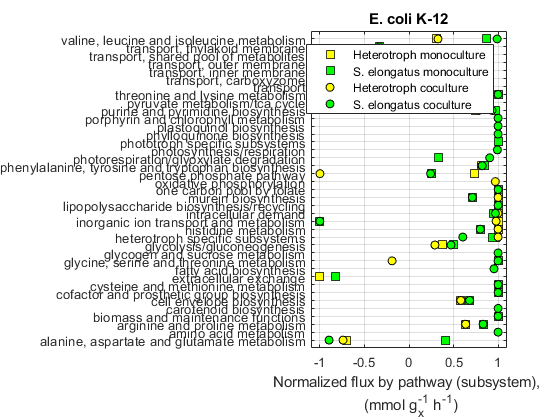


figure
All_subs=All_subsK12;
Y=cellfun(@double,All_subs(:,2)); Y1=cellfun(@double,All_subs(:,3));Y2=cellfun(@double,All_subs(:,4));Y3=cellfun(@double,All_subs(:,5));
plot(Y3,1:length(All_subs),'s','MarkerEdgeColor','k','MarkerFaceColor','y','MarkerSize',8)
hold on
plot(Y2,1:length(All_subs),'s','MarkerEdgeColor','k','MarkerFaceColor','g','MarkerSize',8)
plot(Y1,1:length(All_subs),'o','MarkerEdgeColor','k','MarkerFaceColor','y')
plot(Y,1:length(All_subs),'o','MarkerEdgeColor','k','MarkerFaceColor','g')
hold off
set(gca, 'YTick', 1:length(All_subs), 'YTickLabel', All_subs(1:length(All_subs),1:1));
axis([-1.1 1.1 0 length(All_subs)+1])
legend('Heterotroph monoculture','S. elongatus monoculture','Heterotroph coculture','S. elongatus coculture')
grid on
xlabel(sprintf('Normalized flux by pathway (subsystem), \n (mmol g_x^-^1 h^-^1)'));
title('E. coli K-12')

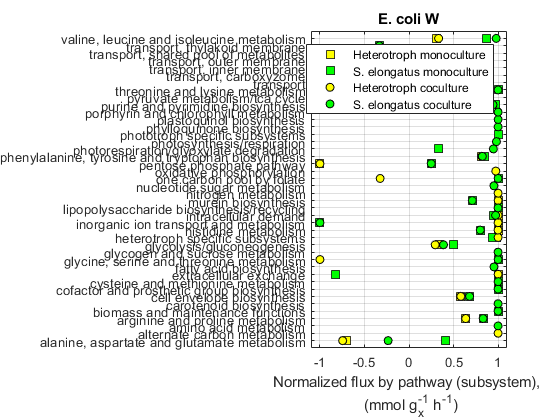


figure
All_subs=All_subsW;
Y=cellfun(@double,All_subs(:,2)); Y1=cellfun(@double,All_subs(:,3));Y2=cellfun(@double,All_subs(:,4));Y3=cellfun(@double,All_subs(:,5));
plot(Y3,1:length(All_subs),'s','MarkerEdgeColor','k','MarkerFaceColor','y','MarkerSize',8)
hold on
plot(Y2,1:length(All_subs),'s','MarkerEdgeColor','k','MarkerFaceColor','g','MarkerSize',8)
plot(Y1,1:length(All_subs),'o','MarkerEdgeColor','k','MarkerFaceColor','y')
plot(Y,1:length(All_subs),'o','MarkerEdgeColor','k','MarkerFaceColor','g')
hold off
set(gca, 'YTick', 1:length(All_subs), 'YTickLabel', All_subs(1:length(All_subs),1:1));
axis([-1.1 1.1 0 length(All_subs)+1])
legend('Heterotroph monoculture','S. elongatus monoculture','Heterotroph coculture','S. elongatus coculture')
grid on
xlabel(sprintf('Normalized flux by pathway (subsystem), \n (mmol g_x^-^1 h^-^1)'));
title('E. coli W')

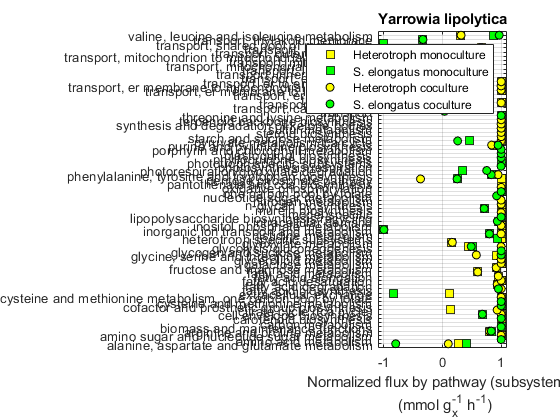


figure
All_subs=All_subsYl;
Y=cellfun(@double,All_subs(:,2)); Y1=cellfun(@double,All_subs(:,3));Y2=cellfun(@double,All_subs(:,4));Y3=cellfun(@double,All_subs(:,5));
plot(Y3,1:length(All_subs),'s','MarkerEdgeColor','k','MarkerFaceColor','y','MarkerSize',8)
hold on
plot(Y2,1:length(All_subs),'s','MarkerEdgeColor','k','MarkerFaceColor','g','MarkerSize',8)
plot(Y1,1:length(All_subs),'o','MarkerEdgeColor','k','MarkerFaceColor','y')
plot(Y,1:length(All_subs),'o','MarkerEdgeColor','k','MarkerFaceColor','g')
hold off
set(gca, 'YTick', 1:length(All_subs), 'YTickLabel', All_subs(1:length(All_subs),1:1));
axis([-1.1 1.1 0 length(All_subs)+1])
legend('Heterotroph monoculture','S. elongatus monoculture','Heterotroph coculture','S. elongatus coculture')
grid on
xlabel(sprintf('Normalized flux by pathway (subsystem), \n (mmol g_x^-^1 h^-^1)'));
title('Yarrowia lipolytica')